# SoundProof box analysis of call detection

I retrieved the audio data collected for 4 pups while they were isolated in soundproof booth under Server2 (169.229.54.49): /server_home/users/old lab members/Sandra/Lesion/Lesionrecordings/Lesion_Groups

These data were collected using the Gui matlab program Lesion under server_home/users/old lab members/Sandra/CODE_current/

Path2Audio='/Volumes/server_home-1/users/old lab members/Sandra/Lesion/Lesionrecordings/Lesion_Groups/';
Path2Data='/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
Pups = [4 6 7 8]; % Bats ID: HF4 (65696) DM1 (71351) HF6 (71353) DF2 (71354)
DOB = [20160819 20160914 20160924 20160927];
DOD = [20160919 20161016 20161015 20161028];
DOD2 = [19+31 16+31+30 15+31+30 28+31+30]; % number of days with reference to august

Loop through folders and files to retrieve the list of mat files with data for the 4 pups both after they were born (one day before)

ListFiles = cell(1,length(Pups));
ListFileNames = cell(1,length(Pups));
for pp=1:length(Pups)
    fprintf(1, 'Pup %d/%d\n', pp, length(Pups))
    Folders = dir(fullfile(Path2Audio, sprintf('Group%d',Pups(pp)),sprintf('Group%d_20*',Pups(pp))));
    ListFiles{pp} = cell(1,length(Folders));
    ListFileNames{pp} = cell(1,length(Folders));
    for ff=1:length(Folders)
        % fprintf(1, '    Folder %d/%d\n', ff, length(Folders))
        Files = dir(fullfile(Folders(ff).folder, Folders(ff).name, 'Group*.mat'));
        ListFiles{pp}{ff} = cell(1,length(Files));
        ListFileNames{pp}{ff} = cell(1,length(Files));
        CountFile = 0;
        for ffile = 1:length(Files)
            Ind_ = strfind(Files(ffile).name, '_');
            Date = str2double(Files(ffile).name(Ind_(1) + (1:8)));
            if Date>=(DOB(pp)-1)
                CountFile = CountFile +1;
                ListFiles{pp}{ff}{CountFile} = fullfile(Files(ffile).folder, Files(ffile).name);
                ListFileNames{pp}{ff}{CountFile} = Files(ffile).name;
            end
        end
        ListFiles{pp}{ff} = ListFiles{pp}{ff}(1:CountFile);
        ListFileNames{pp}{ff} = ListFileNames{pp}{ff}(1:CountFile);
    end
    ListFiles{pp} = ([ListFiles{pp}{:}]);
    ListFileNames{pp} = ([ListFileNames{pp}{:}]);
end

Pup 1/4
Pup 2/4
Pup 3/4
Pup 4/4


ListFiles = [ListFiles{:}]';
ListFileNames = [ListFileNames{:}]';
[~,UFile,~] = unique(ListFileNames);
ListFiles = ListFiles(UFile);
save(fullfile(Path2Audio, 'DataBooths.mat'), 'ListFiles')

Gather dates

load(fullfile(Path2Audio, 'DataBooths.mat'), 'ListFiles');
IDDates_all = nan(size(ListFiles));
for ffile=1:length(ListFiles)
    [~, Name,~]=fileparts(ListFiles{ffile});
    Ind_ = strfind(Name, '_');
    IDDates_all(ffile) = str2double([Name(Ind_(1)-1) Name(Ind_(1) + (3:8))]); % combine both the pup ID and the date of recording sprintf('%d%d',PupID,yymmdd) 
end
UIDDate = unique(IDDates_all);

Convert the data into a format that could be used by ResNet trained on adult deaf and hearing vocalizations (the approach on inferring on pups data with ResNet trained on adult vocalizations did not work at all, so I manually annotated calls with who_calls_soundproofBooth.m and trained a neural net per pup data to accomodate for microphone differences). The following code though was useful to train the neural net. 

Debug=0; %set to 1 to see debug figure
NVoc = 100; % max number of voc per file
VolFactorMic = 0.5;
FS= 192000; % Hz
FS_out = 50000; % Hz
DB_noise = 60;
FHigh_spec_Logger = 25000;
% design filters of raw ambient recording, bandpass 100Hz - 10kHz
[z,p,k] = butter(6,[100 20000]/(FS/2),'bandpass');
sos_raw_band = zp2sos(z,p,k);
[z,p,k] = butter(6,[100 9000]/(FS/20),'bandpass'); % create a filter for data as if the sampling rate was 10 times slower to capture higher pitch vocalizations
sos_raw_band_down = zp2sos(z,p,k);
for dd=1:length(UIDDate)
    UIDDate_str = num2str(UIDDate(dd));
    PupID = num2str(UIDDate_str(1));
    fprintf(1, 'Recording day 20%s Pup%s (%d/%d)\n', UIDDate_str(2:end), PupID, dd, length(UIDDate))
    NumFilesOut = ceil(sum(IDDates_all==UIDDate(dd))/NVoc);
    FileIndices = find(IDDates_all==UIDDate(dd));
    mkdir(fullfile(Path2Data, ['20' UIDDate_str(2:end)]))
    for ff=1:NumFilesOut
        fprintf(1, 'File of 100 voc %d/%d\n', ff, NumFilesOut)
        if ff<NumFilesOut
            NVocLocal = NVoc;
        elseif ff==NumFilesOut
            NVocLocal = length(FileIndices) - NVoc*(ff-1);
        end
        SoundOut_all = cell(NVocLocal,1);
        SoundOut_down_all = cell(NVocLocal,1);
        FS_out_all = cell(NVocLocal,1);
        Time_voc_all = cell(NVocLocal,1);
        ListFiles_local = ListFiles(FileIndices((ff-1)*NVoc + (1:NVocLocal)));
        parfor vv=1:NVocLocal
            Sound = load(ListFiles_local{vv});
            [~,NameIn,~]=fileparts(ListFiles_local{vv});
            IndT = strfind(NameIn,'T');
            Time_voc = NameIn(IndT + (1:6));
            if Sound.fs~=FS
                warning('the extract does not have the expected sampling frequency\n')
                
            end
            % filter to 20kHz
            SoundFilt = filtfilt(sos_raw_band,1,Sound.recsGroup);
            SounddownFilt = filtfilt(sos_raw_band_down,1,Sound.recsGroup);
            % downsample to 50kHz
            SoundOut = resample(SoundFilt,FS_out,FS);
            SounddownOut = resample(SounddownFilt,FS_out,FS/10);
            if Debug
                figure(1); set(gcf,'Visible','on'); clf; subplot(3,1,1); plot(Sound.recsGroup); xlim([0 length(Sound.recsGroup)]); ylabel('original'); subplot(3,1,2); plot(SoundFilt); xlim([0 length(SoundFilt)]); ylabel('Filtered'); subplot(3,1,3); plot(SoundOut); xlim([0 length(SoundOut)]); ylabel('Filt+downsampled');
                suplabel(sprintf('Pup%s %s %s voc %d/%d', PupID, UIDDate_str(2:end),Time_voc,(ff-1)*NVoc + vv, length(FileIndices)),'t');
                figure(2); set(gcf,'Visible','on'); clf;
                subplot(5,1,1)
                [~] = spec_only_bats(Sound.recsGroup, Sound.fs, DB_noise, 90000);
                subplot(5,1,2)
                [~] = spec_only_bats(SoundFilt, Sound.fs, DB_noise, FHigh_spec_Logger);
                subplot(5,1,3)
                [~] = spec_only_bats(SoundOut, FS_out, DB_noise, FHigh_spec_Logger);
                subplot(5,1,4)
                [~] = spec_only_bats(SounddownFilt, Sound.fs/10, DB_noise, FHigh_spec_Logger);
                subplot(5,1,5)
                [~] = spec_only_bats(SounddownOut, FS_out, DB_noise, FHigh_spec_Logger);
                suplabel(sprintf('Pup%s %s %s voc %d/%d', PupID, UIDDate_str(2:end),Time_voc,(ff-1)*NVoc + vv, length(FileIndices)),'t');
                
                SampleMic = resample((SoundFilt - mean(SoundFilt))/(std(SoundFilt)/VolFactorMic),FS/4,FS);
                PlayerMic= audioplayer(SampleMic, FS/4,24);
                play(PlayerMic)
                pause(1)
            end
            %save
            SoundOut_all{vv} = SoundOut;
            SoundOut_down_all{vv} = SounddownOut;
            FS_out_all{vv} = FS_out;
            Time_voc_all{vv} = Time_voc;
        end
        Mic_wave.(sprintf('Logger%s',PupID)) = SoundOut_all;% I will need to change the WAVE_KEY and FS_KEY in generate_infer.py
        Mic_wavedown.(sprintf('Logger%s',PupID)) = SoundOut_down_all;
        Mic_FS.(sprintf('Logger%s',PupID)) = cell2mat(FS_out_all);
        Mic_Time.(sprintf('Logger%s',PupID)) = Time_voc_all;
        save(fullfile(Path2Data, ['20' UIDDate_str(2:end)], sprintf('%s_%s_VocExtractData%d.mat', UIDDate_str(2:end), repmat(UIDDate_str(1),1,4),ff)), "Mic_wave",'Mic_wavedown', 'Mic_FS', 'Mic_Time')
        clear Mic_wave Mic_wavedown Mic_FS Mic_Time
    end
end

Recording day 20160727 Pup4 (1/236)


File of 100 voc 1/1


Recording day 20160728 Pup4 (2/236)


File of 100 voc 1/21
File of 100 voc 2/21
File of 100 voc 3/21
File of 100 voc 4/21
File of 100 voc 5/21
File of 100 voc 6/21
File of 100 voc 7/21
File of 100 voc 8/21
File of 100 voc 9/21
File of 100 voc 10/21
File of 100 voc 11/21
File of 100 voc 12/21
File of 100 voc 13/21
File of 100 voc 14/21
File of 100 voc 15/21
File of 100 voc 16/21
File of 100 voc 17/21
File of 100 voc 18/21
File of 100 voc 19/21
File of 100 voc 20/21
File of 100 voc 21/21


Recording day 20160729 Pup4 (3/236)


File of 100 voc 1/31
File of 100 voc 2/31
File of 100 voc 3/31
File of 100 voc 4/31
File of 100 voc 5/31
File of 100 voc 6/31
File of 100 voc 7/31
File of 100 voc 8/31
File of 100 voc 9/31
File of 100 voc 10/31
File of 100 voc 11/31
File of 100 voc 12/31
File of 100 voc 13/31
File of 100 voc 14/31
File of 100 voc 15/31
File of 100 voc 16/31
File of 100 voc 17/31
File of 100 voc 18/31
File of 100 voc 19/31
File of 100 voc 20/31
File of 100 voc 21/31
File of 100 voc 22/31
File of 100 voc 23/31
File of 100 voc 24/31
File of 100 voc 25/31
File of 100 voc 26/31
File of 100 voc 27/31
File of 100 voc 28/31
File of 100 voc 29/31
File of 100 voc 30/31
File of 100 voc 31/31


Recording day 20160818 Pup4 (4/236)


File of 100 voc 1/35
File of 100 voc 2/35
File of 100 voc 3/35
File of 100 voc 4/35
File of 100 voc 5/35
File of 100 voc 6/35
File of 100 voc 7/35
File of 100 voc 8/35
File of 100 voc 9/35
File of 100 voc 10/35
File of 100 voc 11/35
File of 100 voc 12/35
File of 100 voc 13/35
File of 100 voc 14/35
File of 100 voc 15/35
File of 100 voc 16/35
File of 100 voc 17/35
File of 100 voc 18/35
File of 100 voc 19/35
File of 100 voc 20/35
File of 100 voc 21/35
File of 100 voc 22/35
File of 100 voc 23/35
File of 100 voc 24/35
File of 100 voc 25/35
File of 100 voc 26/35
File of 100 voc 27/35
File of 100 voc 28/35
File of 100 voc 29/35
File of 100 voc 30/35
File of 100 voc 31/35
File of 100 voc 32/35
File of 100 voc 33/35
File of 100 voc 34/35
File of 100 voc 35/35


Recording day 20160819 Pup4 (5/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20160820 Pup4 (6/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20160821 Pup4 (7/236)


File of 100 voc 1/20
File of 100 voc 2/20
File of 100 voc 3/20
File of 100 voc 4/20
File of 100 voc 5/20
File of 100 voc 6/20
File of 100 voc 7/20
File of 100 voc 8/20
File of 100 voc 9/20
File of 100 voc 10/20
File of 100 voc 11/20
File of 100 voc 12/20
File of 100 voc 13/20
File of 100 voc 14/20
File of 100 voc 15/20
File of 100 voc 16/20
File of 100 voc 17/20
File of 100 voc 18/20
File of 100 voc 19/20
File of 100 voc 20/20


Recording day 20160822 Pup4 (8/236)


File of 100 voc 1/20
File of 100 voc 2/20
File of 100 voc 3/20
File of 100 voc 4/20
File of 100 voc 5/20
File of 100 voc 6/20
File of 100 voc 7/20
File of 100 voc 8/20
File of 100 voc 9/20
File of 100 voc 10/20
File of 100 voc 11/20
File of 100 voc 12/20
File of 100 voc 13/20
File of 100 voc 14/20
File of 100 voc 15/20
File of 100 voc 16/20
File of 100 voc 17/20
File of 100 voc 18/20
File of 100 voc 19/20
File of 100 voc 20/20


Recording day 20160823 Pup4 (9/236)


File of 100 voc 1/25
File of 100 voc 2/25
File of 100 voc 3/25
File of 100 voc 4/25
File of 100 voc 5/25
File of 100 voc 6/25
File of 100 voc 7/25
File of 100 voc 8/25
File of 100 voc 9/25
File of 100 voc 10/25
File of 100 voc 11/25
File of 100 voc 12/25
File of 100 voc 13/25
File of 100 voc 14/25
File of 100 voc 15/25
File of 100 voc 16/25
File of 100 voc 17/25
File of 100 voc 18/25
File of 100 voc 19/25
File of 100 voc 20/25
File of 100 voc 21/25
File of 100 voc 22/25
File of 100 voc 23/25
File of 100 voc 24/25
File of 100 voc 25/25


Recording day 20160824 Pup4 (10/236)


File of 100 voc 1/27
File of 100 voc 2/27
File of 100 voc 3/27
File of 100 voc 4/27
File of 100 voc 5/27
File of 100 voc 6/27
File of 100 voc 7/27
File of 100 voc 8/27
File of 100 voc 9/27
File of 100 voc 10/27
File of 100 voc 11/27
File of 100 voc 12/27
File of 100 voc 13/27
File of 100 voc 14/27
File of 100 voc 15/27
File of 100 voc 16/27
File of 100 voc 17/27
File of 100 voc 18/27
File of 100 voc 19/27
File of 100 voc 20/27
File of 100 voc 21/27
File of 100 voc 22/27
File of 100 voc 23/27
File of 100 voc 24/27
File of 100 voc 25/27
File of 100 voc 26/27
File of 100 voc 27/27


Recording day 20160825 Pup4 (11/236)


File of 100 voc 1/32
File of 100 voc 2/32
File of 100 voc 3/32
File of 100 voc 4/32
File of 100 voc 5/32
File of 100 voc 6/32
File of 100 voc 7/32
File of 100 voc 8/32
File of 100 voc 9/32
File of 100 voc 10/32
File of 100 voc 11/32
File of 100 voc 12/32
File of 100 voc 13/32
File of 100 voc 14/32
File of 100 voc 15/32
File of 100 voc 16/32
File of 100 voc 17/32
File of 100 voc 18/32
File of 100 voc 19/32
File of 100 voc 20/32
File of 100 voc 21/32
File of 100 voc 22/32
File of 100 voc 23/32
File of 100 voc 24/32
File of 100 voc 25/32
File of 100 voc 26/32
File of 100 voc 27/32
File of 100 voc 28/32
File of 100 voc 29/32
File of 100 voc 30/32
File of 100 voc 31/32
File of 100 voc 32/32


Recording day 20160826 Pup4 (12/236)


File of 100 voc 1/29
File of 100 voc 2/29
File of 100 voc 3/29
File of 100 voc 4/29
File of 100 voc 5/29
File of 100 voc 6/29
File of 100 voc 7/29
File of 100 voc 8/29
File of 100 voc 9/29
File of 100 voc 10/29
File of 100 voc 11/29
File of 100 voc 12/29
File of 100 voc 13/29
File of 100 voc 14/29
File of 100 voc 15/29
File of 100 voc 16/29
File of 100 voc 17/29
File of 100 voc 18/29
File of 100 voc 19/29
File of 100 voc 20/29
File of 100 voc 21/29
File of 100 voc 22/29
File of 100 voc 23/29
File of 100 voc 24/29
File of 100 voc 25/29
File of 100 voc 26/29
File of 100 voc 27/29
File of 100 voc 28/29
File of 100 voc 29/29


Recording day 20160827 Pup4 (13/236)


File of 100 voc 1/31
File of 100 voc 2/31
File of 100 voc 3/31
File of 100 voc 4/31
File of 100 voc 5/31
File of 100 voc 6/31
File of 100 voc 7/31
File of 100 voc 8/31
File of 100 voc 9/31
File of 100 voc 10/31
File of 100 voc 11/31
File of 100 voc 12/31
File of 100 voc 13/31
File of 100 voc 14/31
File of 100 voc 15/31
File of 100 voc 16/31
File of 100 voc 17/31
File of 100 voc 18/31
File of 100 voc 19/31
File of 100 voc 20/31
File of 100 voc 21/31
File of 100 voc 22/31
File of 100 voc 23/31
File of 100 voc 24/31
File of 100 voc 25/31
File of 100 voc 26/31
File of 100 voc 27/31
File of 100 voc 28/31
File of 100 voc 29/31
File of 100 voc 30/31
File of 100 voc 31/31


Recording day 20160828 Pup4 (14/236)


File of 100 voc 1/31
File of 100 voc 2/31
File of 100 voc 3/31
File of 100 voc 4/31
File of 100 voc 5/31
File of 100 voc 6/31
File of 100 voc 7/31
File of 100 voc 8/31
File of 100 voc 9/31
File of 100 voc 10/31
File of 100 voc 11/31
File of 100 voc 12/31
File of 100 voc 13/31
File of 100 voc 14/31
File of 100 voc 15/31
File of 100 voc 16/31
File of 100 voc 17/31
File of 100 voc 18/31
File of 100 voc 19/31
File of 100 voc 20/31
File of 100 voc 21/31
File of 100 voc 22/31
File of 100 voc 23/31
File of 100 voc 24/31
File of 100 voc 25/31
File of 100 voc 26/31
File of 100 voc 27/31
File of 100 voc 28/31
File of 100 voc 29/31
File of 100 voc 30/31
File of 100 voc 31/31


Recording day 20160829 Pup4 (15/236)


File of 100 voc 1/31
File of 100 voc 2/31
File of 100 voc 3/31
File of 100 voc 4/31
File of 100 voc 5/31
File of 100 voc 6/31
File of 100 voc 7/31
File of 100 voc 8/31
File of 100 voc 9/31
File of 100 voc 10/31
File of 100 voc 11/31
File of 100 voc 12/31
File of 100 voc 13/31
File of 100 voc 14/31
File of 100 voc 15/31
File of 100 voc 16/31
File of 100 voc 17/31
File of 100 voc 18/31
File of 100 voc 19/31
File of 100 voc 20/31
File of 100 voc 21/31
File of 100 voc 22/31
File of 100 voc 23/31
File of 100 voc 24/31
File of 100 voc 25/31
File of 100 voc 26/31
File of 100 voc 27/31
File of 100 voc 28/31
File of 100 voc 29/31
File of 100 voc 30/31
File of 100 voc 31/31


Recording day 20160830 Pup4 (16/236)


File of 100 voc 1/28
File of 100 voc 2/28
File of 100 voc 3/28
File of 100 voc 4/28
File of 100 voc 5/28
File of 100 voc 6/28
File of 100 voc 7/28
File of 100 voc 8/28
File of 100 voc 9/28
File of 100 voc 10/28
File of 100 voc 11/28
File of 100 voc 12/28
File of 100 voc 13/28
File of 100 voc 14/28
File of 100 voc 15/28
File of 100 voc 16/28
File of 100 voc 17/28
File of 100 voc 18/28
File of 100 voc 19/28
File of 100 voc 20/28
File of 100 voc 21/28
File of 100 voc 22/28
File of 100 voc 23/28
File of 100 voc 24/28
File of 100 voc 25/28
File of 100 voc 26/28
File of 100 voc 27/28
File of 100 voc 28/28


Recording day 20160831 Pup4 (17/236)


File of 100 voc 1/31
File of 100 voc 2/31
File of 100 voc 3/31
File of 100 voc 4/31
File of 100 voc 5/31
File of 100 voc 6/31
File of 100 voc 7/31
File of 100 voc 8/31
File of 100 voc 9/31
File of 100 voc 10/31
File of 100 voc 11/31
File of 100 voc 12/31
File of 100 voc 13/31
File of 100 voc 14/31
File of 100 voc 15/31
File of 100 voc 16/31
File of 100 voc 17/31
File of 100 voc 18/31
File of 100 voc 19/31
File of 100 voc 20/31
File of 100 voc 21/31
File of 100 voc 22/31
File of 100 voc 23/31
File of 100 voc 24/31
File of 100 voc 25/31
File of 100 voc 26/31
File of 100 voc 27/31
File of 100 voc 28/31
File of 100 voc 29/31
File of 100 voc 30/31
File of 100 voc 31/31


Recording day 20160901 Pup4 (18/236)


File of 100 voc 1/22
File of 100 voc 2/22
File of 100 voc 3/22
File of 100 voc 4/22
File of 100 voc 5/22
File of 100 voc 6/22
File of 100 voc 7/22
File of 100 voc 8/22
File of 100 voc 9/22
File of 100 voc 10/22
File of 100 voc 11/22
File of 100 voc 12/22
File of 100 voc 13/22
File of 100 voc 14/22
File of 100 voc 15/22
File of 100 voc 16/22
File of 100 voc 17/22
File of 100 voc 18/22
File of 100 voc 19/22
File of 100 voc 20/22
File of 100 voc 21/22
File of 100 voc 22/22


Recording day 20160902 Pup4 (19/236)


File of 100 voc 1/29
File of 100 voc 2/29
File of 100 voc 3/29
File of 100 voc 4/29
File of 100 voc 5/29
File of 100 voc 6/29
File of 100 voc 7/29
File of 100 voc 8/29
File of 100 voc 9/29
File of 100 voc 10/29
File of 100 voc 11/29
File of 100 voc 12/29
File of 100 voc 13/29
File of 100 voc 14/29
File of 100 voc 15/29
File of 100 voc 16/29
File of 100 voc 17/29
File of 100 voc 18/29
File of 100 voc 19/29
File of 100 voc 20/29
File of 100 voc 21/29
File of 100 voc 22/29
File of 100 voc 23/29
File of 100 voc 24/29
File of 100 voc 25/29
File of 100 voc 26/29
File of 100 voc 27/29
File of 100 voc 28/29
File of 100 voc 29/29


Recording day 20160903 Pup4 (20/236)


File of 100 voc 1/24
File of 100 voc 2/24
File of 100 voc 3/24
File of 100 voc 4/24
File of 100 voc 5/24
File of 100 voc 6/24
File of 100 voc 7/24
File of 100 voc 8/24
File of 100 voc 9/24
File of 100 voc 10/24
File of 100 voc 11/24
File of 100 voc 12/24
File of 100 voc 13/24
File of 100 voc 14/24
File of 100 voc 15/24
File of 100 voc 16/24
File of 100 voc 17/24
File of 100 voc 18/24
File of 100 voc 19/24
File of 100 voc 20/24
File of 100 voc 21/24
File of 100 voc 22/24
File of 100 voc 23/24
File of 100 voc 24/24


Recording day 20160904 Pup4 (21/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20160905 Pup4 (22/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20160906 Pup4 (23/236)


File of 100 voc 1/17
File of 100 voc 2/17
File of 100 voc 3/17
File of 100 voc 4/17
File of 100 voc 5/17
File of 100 voc 6/17
File of 100 voc 7/17
File of 100 voc 8/17
File of 100 voc 9/17
File of 100 voc 10/17
File of 100 voc 11/17
File of 100 voc 12/17
File of 100 voc 13/17
File of 100 voc 14/17
File of 100 voc 15/17
File of 100 voc 16/17
File of 100 voc 17/17


Recording day 20160907 Pup4 (24/236)


File of 100 voc 1/22
File of 100 voc 2/22
File of 100 voc 3/22
File of 100 voc 4/22
File of 100 voc 5/22
File of 100 voc 6/22
File of 100 voc 7/22
File of 100 voc 8/22
File of 100 voc 9/22
File of 100 voc 10/22
File of 100 voc 11/22
File of 100 voc 12/22
File of 100 voc 13/22
File of 100 voc 14/22
File of 100 voc 15/22
File of 100 voc 16/22
File of 100 voc 17/22
File of 100 voc 18/22
File of 100 voc 19/22
File of 100 voc 20/22
File of 100 voc 21/22
File of 100 voc 22/22


Recording day 20160908 Pup4 (25/236)


File of 100 voc 1/16
File of 100 voc 2/16
File of 100 voc 3/16
File of 100 voc 4/16
File of 100 voc 5/16
File of 100 voc 6/16
File of 100 voc 7/16
File of 100 voc 8/16
File of 100 voc 9/16
File of 100 voc 10/16
File of 100 voc 11/16
File of 100 voc 12/16
File of 100 voc 13/16
File of 100 voc 14/16
File of 100 voc 15/16
File of 100 voc 16/16


Recording day 20160909 Pup4 (26/236)


File of 100 voc 1/30
File of 100 voc 2/30
File of 100 voc 3/30
File of 100 voc 4/30
File of 100 voc 5/30
File of 100 voc 6/30
File of 100 voc 7/30
File of 100 voc 8/30
File of 100 voc 9/30
File of 100 voc 10/30
File of 100 voc 11/30
File of 100 voc 12/30
File of 100 voc 13/30
File of 100 voc 14/30
File of 100 voc 15/30
File of 100 voc 16/30
File of 100 voc 17/30
File of 100 voc 18/30
File of 100 voc 19/30
File of 100 voc 20/30
File of 100 voc 21/30
File of 100 voc 22/30
File of 100 voc 23/30
File of 100 voc 24/30
File of 100 voc 25/30
File of 100 voc 26/30
File of 100 voc 27/30
File of 100 voc 28/30
File of 100 voc 29/30
File of 100 voc 30/30


Recording day 20160910 Pup4 (27/236)


File of 100 voc 1/39
File of 100 voc 2/39
File of 100 voc 3/39
File of 100 voc 4/39
File of 100 voc 5/39
File of 100 voc 6/39
File of 100 voc 7/39
File of 100 voc 8/39
File of 100 voc 9/39
File of 100 voc 10/39
File of 100 voc 11/39
File of 100 voc 12/39
File of 100 voc 13/39
File of 100 voc 14/39
File of 100 voc 15/39
File of 100 voc 16/39
File of 100 voc 17/39
File of 100 voc 18/39
File of 100 voc 19/39
File of 100 voc 20/39
File of 100 voc 21/39
File of 100 voc 22/39
File of 100 voc 23/39
File of 100 voc 24/39
File of 100 voc 25/39
File of 100 voc 26/39
File of 100 voc 27/39
File of 100 voc 28/39
File of 100 voc 29/39
File of 100 voc 30/39
File of 100 voc 31/39
File of 100 voc 32/39
File of 100 voc 33/39
File of 100 voc 34/39
File of 100 voc 35/39
File of 100 voc 36/39
File of 100 voc 37/39
File of 100 voc 38/39
File of 100 voc 39/39


Recording day 20160911 Pup4 (28/236)


File of 100 voc 1/31
File of 100 voc 2/31
File of 100 voc 3/31
File of 100 voc 4/31
File of 100 voc 5/31
File of 100 voc 6/31
File of 100 voc 7/31
File of 100 voc 8/31
File of 100 voc 9/31
File of 100 voc 10/31
File of 100 voc 11/31
File of 100 voc 12/31
File of 100 voc 13/31
File of 100 voc 14/31
File of 100 voc 15/31
File of 100 voc 16/31
File of 100 voc 17/31
File of 100 voc 18/31
File of 100 voc 19/31
File of 100 voc 20/31
File of 100 voc 21/31
File of 100 voc 22/31
File of 100 voc 23/31
File of 100 voc 24/31
File of 100 voc 25/31
File of 100 voc 26/31
File of 100 voc 27/31
File of 100 voc 28/31
File of 100 voc 29/31
File of 100 voc 30/31
File of 100 voc 31/31


Recording day 20160912 Pup4 (29/236)


File of 100 voc 1/35
File of 100 voc 2/35
File of 100 voc 3/35
File of 100 voc 4/35
File of 100 voc 5/35
File of 100 voc 6/35
File of 100 voc 7/35
File of 100 voc 8/35
File of 100 voc 9/35
File of 100 voc 10/35
File of 100 voc 11/35
File of 100 voc 12/35
File of 100 voc 13/35
File of 100 voc 14/35
File of 100 voc 15/35
File of 100 voc 16/35
File of 100 voc 17/35
File of 100 voc 18/35
File of 100 voc 19/35
File of 100 voc 20/35
File of 100 voc 21/35
File of 100 voc 22/35
File of 100 voc 23/35
File of 100 voc 24/35
File of 100 voc 25/35
File of 100 voc 26/35
File of 100 voc 27/35
File of 100 voc 28/35
File of 100 voc 29/35
File of 100 voc 30/35
File of 100 voc 31/35
File of 100 voc 32/35
File of 100 voc 33/35
File of 100 voc 34/35
File of 100 voc 35/35


Recording day 20160913 Pup4 (30/236)


File of 100 voc 1/35
File of 100 voc 2/35
File of 100 voc 3/35
File of 100 voc 4/35
File of 100 voc 5/35
File of 100 voc 6/35
File of 100 voc 7/35
File of 100 voc 8/35
File of 100 voc 9/35
File of 100 voc 10/35
File of 100 voc 11/35
File of 100 voc 12/35
File of 100 voc 13/35
File of 100 voc 14/35
File of 100 voc 15/35
File of 100 voc 16/35
File of 100 voc 17/35
File of 100 voc 18/35
File of 100 voc 19/35
File of 100 voc 20/35
File of 100 voc 21/35
File of 100 voc 22/35
File of 100 voc 23/35
File of 100 voc 24/35
File of 100 voc 25/35
File of 100 voc 26/35
File of 100 voc 27/35
File of 100 voc 28/35
File of 100 voc 29/35
File of 100 voc 30/35
File of 100 voc 31/35
File of 100 voc 32/35
File of 100 voc 33/35
File of 100 voc 34/35
File of 100 voc 35/35


Recording day 20160914 Pup4 (31/236)


File of 100 voc 1/34
File of 100 voc 2/34
File of 100 voc 3/34
File of 100 voc 4/34
File of 100 voc 5/34
File of 100 voc 6/34
File of 100 voc 7/34
File of 100 voc 8/34
File of 100 voc 9/34
File of 100 voc 10/34
File of 100 voc 11/34
File of 100 voc 12/34
File of 100 voc 13/34
File of 100 voc 14/34
File of 100 voc 15/34
File of 100 voc 16/34
File of 100 voc 17/34
File of 100 voc 18/34
File of 100 voc 19/34
File of 100 voc 20/34
File of 100 voc 21/34
File of 100 voc 22/34
File of 100 voc 23/34
File of 100 voc 24/34
File of 100 voc 25/34
File of 100 voc 26/34
File of 100 voc 27/34
File of 100 voc 28/34
File of 100 voc 29/34
File of 100 voc 30/34
File of 100 voc 31/34
File of 100 voc 32/34
File of 100 voc 33/34
File of 100 voc 34/34


Recording day 20160915 Pup4 (32/236)


File of 100 voc 1/29
File of 100 voc 2/29
File of 100 voc 3/29
File of 100 voc 4/29
File of 100 voc 5/29
File of 100 voc 6/29
File of 100 voc 7/29
File of 100 voc 8/29
File of 100 voc 9/29
File of 100 voc 10/29
File of 100 voc 11/29
File of 100 voc 12/29
File of 100 voc 13/29
File of 100 voc 14/29
File of 100 voc 15/29
File of 100 voc 16/29
File of 100 voc 17/29
File of 100 voc 18/29
File of 100 voc 19/29
File of 100 voc 20/29
File of 100 voc 21/29
File of 100 voc 22/29
File of 100 voc 23/29
File of 100 voc 24/29
File of 100 voc 25/29
File of 100 voc 26/29
File of 100 voc 27/29
File of 100 voc 28/29
File of 100 voc 29/29


Recording day 20160916 Pup4 (33/236)


File of 100 voc 1/18
File of 100 voc 2/18
File of 100 voc 3/18
File of 100 voc 4/18
File of 100 voc 5/18
File of 100 voc 6/18
File of 100 voc 7/18
File of 100 voc 8/18
File of 100 voc 9/18
File of 100 voc 10/18
File of 100 voc 11/18
File of 100 voc 12/18
File of 100 voc 13/18
File of 100 voc 14/18
File of 100 voc 15/18
File of 100 voc 16/18
File of 100 voc 17/18
File of 100 voc 18/18


Recording day 20160917 Pup4 (34/236)


File of 100 voc 1/26
File of 100 voc 2/26
File of 100 voc 3/26
File of 100 voc 4/26
File of 100 voc 5/26
File of 100 voc 6/26
File of 100 voc 7/26
File of 100 voc 8/26
File of 100 voc 9/26
File of 100 voc 10/26
File of 100 voc 11/26
File of 100 voc 12/26
File of 100 voc 13/26
File of 100 voc 14/26
File of 100 voc 15/26
File of 100 voc 16/26
File of 100 voc 17/26
File of 100 voc 18/26
File of 100 voc 19/26
File of 100 voc 20/26
File of 100 voc 21/26
File of 100 voc 22/26
File of 100 voc 23/26
File of 100 voc 24/26
File of 100 voc 25/26
File of 100 voc 26/26


Recording day 20160918 Pup4 (35/236)


File of 100 voc 1/34
File of 100 voc 2/34
File of 100 voc 3/34
File of 100 voc 4/34
File of 100 voc 5/34
File of 100 voc 6/34
File of 100 voc 7/34
File of 100 voc 8/34
File of 100 voc 9/34
File of 100 voc 10/34
File of 100 voc 11/34
File of 100 voc 12/34
File of 100 voc 13/34
File of 100 voc 14/34
File of 100 voc 15/34
File of 100 voc 16/34
File of 100 voc 17/34
File of 100 voc 18/34
File of 100 voc 19/34
File of 100 voc 20/34
File of 100 voc 21/34
File of 100 voc 22/34
File of 100 voc 23/34
File of 100 voc 24/34
File of 100 voc 25/34
File of 100 voc 26/34
File of 100 voc 27/34
File of 100 voc 28/34
File of 100 voc 29/34
File of 100 voc 30/34
File of 100 voc 31/34
File of 100 voc 32/34
File of 100 voc 33/34
File of 100 voc 34/34


Recording day 20160919 Pup4 (36/236)


File of 100 voc 1/32
File of 100 voc 2/32
File of 100 voc 3/32
File of 100 voc 4/32
File of 100 voc 5/32
File of 100 voc 6/32
File of 100 voc 7/32
File of 100 voc 8/32
File of 100 voc 9/32
File of 100 voc 10/32
File of 100 voc 11/32
File of 100 voc 12/32
File of 100 voc 13/32
File of 100 voc 14/32
File of 100 voc 15/32
File of 100 voc 16/32
File of 100 voc 17/32
File of 100 voc 18/32
File of 100 voc 19/32
File of 100 voc 20/32
File of 100 voc 21/32
File of 100 voc 22/32
File of 100 voc 23/32
File of 100 voc 24/32
File of 100 voc 25/32
File of 100 voc 26/32
File of 100 voc 27/32
File of 100 voc 28/32
File of 100 voc 29/32
File of 100 voc 30/32
File of 100 voc 31/32
File of 100 voc 32/32


Recording day 20160920 Pup4 (37/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20160921 Pup4 (38/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20160922 Pup4 (39/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20160923 Pup4 (40/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20160924 Pup4 (41/236)


File of 100 voc 1/16
File of 100 voc 2/16
File of 100 voc 3/16
File of 100 voc 4/16
File of 100 voc 5/16
File of 100 voc 6/16
File of 100 voc 7/16
File of 100 voc 8/16
File of 100 voc 9/16
File of 100 voc 10/16
File of 100 voc 11/16
File of 100 voc 12/16
File of 100 voc 13/16
File of 100 voc 14/16
File of 100 voc 15/16
File of 100 voc 16/16


Recording day 20160925 Pup4 (42/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20160926 Pup4 (43/236)


File of 100 voc 1/18
File of 100 voc 2/18
File of 100 voc 3/18
File of 100 voc 4/18
File of 100 voc 5/18
File of 100 voc 6/18
File of 100 voc 7/18
File of 100 voc 8/18
File of 100 voc 9/18
File of 100 voc 10/18
File of 100 voc 11/18
File of 100 voc 12/18
File of 100 voc 13/18
File of 100 voc 14/18
File of 100 voc 15/18
File of 100 voc 16/18
File of 100 voc 17/18
File of 100 voc 18/18


Recording day 20160927 Pup4 (44/236)


File of 100 voc 1/17
File of 100 voc 2/17
File of 100 voc 3/17
File of 100 voc 4/17
File of 100 voc 5/17
File of 100 voc 6/17
File of 100 voc 7/17
File of 100 voc 8/17
File of 100 voc 9/17
File of 100 voc 10/17
File of 100 voc 11/17
File of 100 voc 12/17
File of 100 voc 13/17
File of 100 voc 14/17
File of 100 voc 15/17
File of 100 voc 16/17
File of 100 voc 17/17


Recording day 20160928 Pup4 (45/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20160929 Pup4 (46/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20160930 Pup4 (47/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161001 Pup4 (48/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161002 Pup4 (49/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161003 Pup4 (50/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161004 Pup4 (51/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161005 Pup4 (52/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161006 Pup4 (53/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161007 Pup4 (54/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161008 Pup4 (55/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20161009 Pup4 (56/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161010 Pup4 (57/236)


File of 100 voc 1/20
File of 100 voc 2/20
File of 100 voc 3/20
File of 100 voc 4/20
File of 100 voc 5/20
File of 100 voc 6/20
File of 100 voc 7/20
File of 100 voc 8/20
File of 100 voc 9/20
File of 100 voc 10/20
File of 100 voc 11/20
File of 100 voc 12/20
File of 100 voc 13/20
File of 100 voc 14/20
File of 100 voc 15/20
File of 100 voc 16/20
File of 100 voc 17/20
File of 100 voc 18/20
File of 100 voc 19/20
File of 100 voc 20/20


Recording day 20161011 Pup4 (58/236)


File of 100 voc 1/17
File of 100 voc 2/17
File of 100 voc 3/17
File of 100 voc 4/17
File of 100 voc 5/17
File of 100 voc 6/17
File of 100 voc 7/17
File of 100 voc 8/17
File of 100 voc 9/17
File of 100 voc 10/17
File of 100 voc 11/17
File of 100 voc 12/17
File of 100 voc 13/17
File of 100 voc 14/17
File of 100 voc 15/17
File of 100 voc 16/17
File of 100 voc 17/17


Recording day 20161012 Pup4 (59/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161013 Pup4 (60/236)


File of 100 voc 1/6
File of 100 voc 2/6
File of 100 voc 3/6
File of 100 voc 4/6
File of 100 voc 5/6
File of 100 voc 6/6


Recording day 20161014 Pup4 (61/236)


File of 100 voc 1/1


Recording day 20161016 Pup4 (62/236)


File of 100 voc 1/1


Recording day 20161026 Pup4 (63/236)


File of 100 voc 1/1


Recording day 20160914 Pup6 (64/236)


File of 100 voc 1/1


Recording day 20160915 Pup6 (65/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20160916 Pup6 (66/236)


File of 100 voc 1/6
File of 100 voc 2/6
File of 100 voc 3/6
File of 100 voc 4/6
File of 100 voc 5/6
File of 100 voc 6/6


Recording day 20160917 Pup6 (67/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20160918 Pup6 (68/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20160919 Pup6 (69/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20160920 Pup6 (70/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20160921 Pup6 (71/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20160922 Pup6 (72/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20160923 Pup6 (73/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20160924 Pup6 (74/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20160925 Pup6 (75/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20160926 Pup6 (76/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20160927 Pup6 (77/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20160928 Pup6 (78/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20160929 Pup6 (79/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20160930 Pup6 (80/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161001 Pup6 (81/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161002 Pup6 (82/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161003 Pup6 (83/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161004 Pup6 (84/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161005 Pup6 (85/236)


File of 100 voc 1/17
File of 100 voc 2/17
File of 100 voc 3/17
File of 100 voc 4/17
File of 100 voc 5/17
File of 100 voc 6/17
File of 100 voc 7/17
File of 100 voc 8/17
File of 100 voc 9/17
File of 100 voc 10/17
File of 100 voc 11/17
File of 100 voc 12/17
File of 100 voc 13/17
File of 100 voc 14/17
File of 100 voc 15/17
File of 100 voc 16/17
File of 100 voc 17/17


Recording day 20161006 Pup6 (86/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161007 Pup6 (87/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161008 Pup6 (88/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161009 Pup6 (89/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161010 Pup6 (90/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161011 Pup6 (91/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161012 Pup6 (92/236)


File of 100 voc 1/16
File of 100 voc 2/16
File of 100 voc 3/16
File of 100 voc 4/16
File of 100 voc 5/16
File of 100 voc 6/16
File of 100 voc 7/16
File of 100 voc 8/16
File of 100 voc 9/16
File of 100 voc 10/16
File of 100 voc 11/16
File of 100 voc 12/16
File of 100 voc 13/16
File of 100 voc 14/16
File of 100 voc 15/16
File of 100 voc 16/16


Recording day 20161013 Pup6 (93/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161014 Pup6 (94/236)


File of 100 voc 1/19
File of 100 voc 2/19
File of 100 voc 3/19
File of 100 voc 4/19
File of 100 voc 5/19
File of 100 voc 6/19
File of 100 voc 7/19
File of 100 voc 8/19
File of 100 voc 9/19
File of 100 voc 10/19
File of 100 voc 11/19
File of 100 voc 12/19
File of 100 voc 13/19
File of 100 voc 14/19
File of 100 voc 15/19
File of 100 voc 16/19
File of 100 voc 17/19
File of 100 voc 18/19
File of 100 voc 19/19


Recording day 20161015 Pup6 (95/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161016 Pup6 (96/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161017 Pup6 (97/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161018 Pup6 (98/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161019 Pup6 (99/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161020 Pup6 (100/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161021 Pup6 (101/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161022 Pup6 (102/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161023 Pup6 (103/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161024 Pup6 (104/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161025 Pup6 (105/236)


File of 100 voc 1/6
File of 100 voc 2/6
File of 100 voc 3/6
File of 100 voc 4/6
File of 100 voc 5/6
File of 100 voc 6/6


Recording day 20161026 Pup6 (106/236)


File of 100 voc 1/6
File of 100 voc 2/6
File of 100 voc 3/6
File of 100 voc 4/6
File of 100 voc 5/6
File of 100 voc 6/6


Recording day 20161027 Pup6 (107/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161028 Pup6 (108/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161029 Pup6 (109/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161030 Pup6 (110/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161031 Pup6 (111/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161101 Pup6 (112/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161102 Pup6 (113/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161103 Pup6 (114/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161104 Pup6 (115/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161105 Pup6 (116/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161106 Pup6 (117/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161107 Pup6 (118/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161108 Pup6 (119/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161109 Pup6 (120/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161110 Pup6 (121/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20160923 Pup7 (122/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20160924 Pup7 (123/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20160925 Pup7 (124/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20160926 Pup7 (125/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20160927 Pup7 (126/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20160928 Pup7 (127/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20160929 Pup7 (128/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20160930 Pup7 (129/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161001 Pup7 (130/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161002 Pup7 (131/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161003 Pup7 (132/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161004 Pup7 (133/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161005 Pup7 (134/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161006 Pup7 (135/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161007 Pup7 (136/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161008 Pup7 (137/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161009 Pup7 (138/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161010 Pup7 (139/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161011 Pup7 (140/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20161012 Pup7 (141/236)


File of 100 voc 1/2
File of 100 voc 2/2


Recording day 20161013 Pup7 (142/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161014 Pup7 (143/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161015 Pup7 (144/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161016 Pup7 (145/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161017 Pup7 (146/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161018 Pup7 (147/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161019 Pup7 (148/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161020 Pup7 (149/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161021 Pup7 (150/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161022 Pup7 (151/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161023 Pup7 (152/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161024 Pup7 (153/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161025 Pup7 (154/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161026 Pup7 (155/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161027 Pup7 (156/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161028 Pup7 (157/236)


File of 100 voc 1/2
File of 100 voc 2/2


Recording day 20161029 Pup7 (158/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161030 Pup7 (159/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161031 Pup7 (160/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161101 Pup7 (161/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161102 Pup7 (162/236)


File of 100 voc 1/2
File of 100 voc 2/2


Recording day 20161103 Pup7 (163/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161104 Pup7 (164/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161105 Pup7 (165/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161106 Pup7 (166/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161107 Pup7 (167/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161108 Pup7 (168/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161109 Pup7 (169/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161110 Pup7 (170/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161111 Pup7 (171/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161112 Pup7 (172/236)


File of 100 voc 1/4
File of 100 voc 2/4
File of 100 voc 3/4
File of 100 voc 4/4


Recording day 20161113 Pup7 (173/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161114 Pup7 (174/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161115 Pup7 (175/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161116 Pup7 (176/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161117 Pup7 (177/236)


File of 100 voc 1/3
File of 100 voc 2/3
File of 100 voc 3/3


Recording day 20161118 Pup7 (178/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161119 Pup7 (179/236)


File of 100 voc 1/5
File of 100 voc 2/5
File of 100 voc 3/5
File of 100 voc 4/5
File of 100 voc 5/5


Recording day 20161120 Pup7 (180/236)


File of 100 voc 1/1


Recording day 20160927 Pup8 (181/236)


File of 100 voc 1/6
File of 100 voc 2/6
File of 100 voc 3/6
File of 100 voc 4/6
File of 100 voc 5/6
File of 100 voc 6/6


Recording day 20160928 Pup8 (182/236)


File of 100 voc 1/7
File of 100 voc 2/7
File of 100 voc 3/7
File of 100 voc 4/7
File of 100 voc 5/7
File of 100 voc 6/7
File of 100 voc 7/7


Recording day 20160929 Pup8 (183/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20160930 Pup8 (184/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20161001 Pup8 (185/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161002 Pup8 (186/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161003 Pup8 (187/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161004 Pup8 (188/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161005 Pup8 (189/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161006 Pup8 (190/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161007 Pup8 (191/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161008 Pup8 (192/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161009 Pup8 (193/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20161010 Pup8 (194/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161011 Pup8 (195/236)


File of 100 voc 1/16
File of 100 voc 2/16
File of 100 voc 3/16
File of 100 voc 4/16
File of 100 voc 5/16
File of 100 voc 6/16
File of 100 voc 7/16
File of 100 voc 8/16
File of 100 voc 9/16
File of 100 voc 10/16
File of 100 voc 11/16
File of 100 voc 12/16
File of 100 voc 13/16
File of 100 voc 14/16
File of 100 voc 15/16
File of 100 voc 16/16


Recording day 20161012 Pup8 (196/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20161013 Pup8 (197/236)


File of 100 voc 1/15
File of 100 voc 2/15
File of 100 voc 3/15
File of 100 voc 4/15
File of 100 voc 5/15
File of 100 voc 6/15
File of 100 voc 7/15
File of 100 voc 8/15
File of 100 voc 9/15
File of 100 voc 10/15
File of 100 voc 11/15
File of 100 voc 12/15
File of 100 voc 13/15
File of 100 voc 14/15
File of 100 voc 15/15


Recording day 20161014 Pup8 (198/236)


File of 100 voc 1/19
File of 100 voc 2/19
File of 100 voc 3/19
File of 100 voc 4/19
File of 100 voc 5/19
File of 100 voc 6/19
File of 100 voc 7/19
File of 100 voc 8/19
File of 100 voc 9/19
File of 100 voc 10/19
File of 100 voc 11/19
File of 100 voc 12/19
File of 100 voc 13/19
File of 100 voc 14/19
File of 100 voc 15/19
File of 100 voc 16/19
File of 100 voc 17/19
File of 100 voc 18/19
File of 100 voc 19/19


Recording day 20161015 Pup8 (199/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161016 Pup8 (200/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161017 Pup8 (201/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161018 Pup8 (202/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161019 Pup8 (203/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161020 Pup8 (204/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161021 Pup8 (205/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161022 Pup8 (206/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161023 Pup8 (207/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161024 Pup8 (208/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161025 Pup8 (209/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161026 Pup8 (210/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161027 Pup8 (211/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161028 Pup8 (212/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161029 Pup8 (213/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161030 Pup8 (214/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161031 Pup8 (215/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161101 Pup8 (216/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161102 Pup8 (217/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161103 Pup8 (218/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161104 Pup8 (219/236)


File of 100 voc 1/12
File of 100 voc 2/12
File of 100 voc 3/12
File of 100 voc 4/12
File of 100 voc 5/12
File of 100 voc 6/12
File of 100 voc 7/12
File of 100 voc 8/12
File of 100 voc 9/12
File of 100 voc 10/12
File of 100 voc 11/12
File of 100 voc 12/12


Recording day 20161105 Pup8 (220/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161106 Pup8 (221/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161107 Pup8 (222/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161108 Pup8 (223/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161109 Pup8 (224/236)


File of 100 voc 1/10
File of 100 voc 2/10
File of 100 voc 3/10
File of 100 voc 4/10
File of 100 voc 5/10
File of 100 voc 6/10
File of 100 voc 7/10
File of 100 voc 8/10
File of 100 voc 9/10
File of 100 voc 10/10


Recording day 20161110 Pup8 (225/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161111 Pup8 (226/236)


File of 100 voc 1/9
File of 100 voc 2/9
File of 100 voc 3/9
File of 100 voc 4/9
File of 100 voc 5/9
File of 100 voc 6/9
File of 100 voc 7/9
File of 100 voc 8/9
File of 100 voc 9/9


Recording day 20161112 Pup8 (227/236)


File of 100 voc 1/8
File of 100 voc 2/8
File of 100 voc 3/8
File of 100 voc 4/8
File of 100 voc 5/8
File of 100 voc 6/8
File of 100 voc 7/8
File of 100 voc 8/8


Recording day 20161113 Pup8 (228/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161114 Pup8 (229/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161115 Pup8 (230/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161116 Pup8 (231/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161117 Pup8 (232/236)


File of 100 voc 1/13
File of 100 voc 2/13
File of 100 voc 3/13
File of 100 voc 4/13
File of 100 voc 5/13
File of 100 voc 6/13
File of 100 voc 7/13
File of 100 voc 8/13
File of 100 voc 9/13
File of 100 voc 10/13
File of 100 voc 11/13
File of 100 voc 12/13
File of 100 voc 13/13


Recording day 20161118 Pup8 (233/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161119 Pup8 (234/236)


File of 100 voc 1/11
File of 100 voc 2/11
File of 100 voc 3/11
File of 100 voc 4/11
File of 100 voc 5/11
File of 100 voc 6/11
File of 100 voc 7/11
File of 100 voc 8/11
File of 100 voc 9/11
File of 100 voc 10/11
File of 100 voc 11/11


Recording day 20161120 Pup8 (235/236)


File of 100 voc 1/14
File of 100 voc 2/14
File of 100 voc 3/14
File of 100 voc 4/14
File of 100 voc 5/14
File of 100 voc 6/14
File of 100 voc 7/14
File of 100 voc 8/14
File of 100 voc 9/14
File of 100 voc 10/14
File of 100 voc 11/14
File of 100 voc 12/14
File of 100 voc 13/14
File of 100 voc 14/14


Recording day 20161121 Pup8 (236/236)


File of 100 voc 1/28
File of 100 voc 2/28
File of 100 voc 3/28
File of 100 voc 4/28
File of 100 voc 5/28
File of 100 voc 6/28
File of 100 voc 7/28
File of 100 voc 8/28
File of 100 voc 9/28
File of 100 voc 10/28
File of 100 voc 11/28
File of 100 voc 12/28
File of 100 voc 13/28
File of 100 voc 14/28
File of 100 voc 15/28
File of 100 voc 16/28
File of 100 voc 17/28
File of 100 voc 18/28
File of 100 voc 19/28
File of 100 voc 20/28
File of 100 voc 21/28
File of 100 voc 22/28
File of 100 voc 23/28
File of 100 voc 24/28
File of 100 voc 25/28
File of 100 voc 26/28
File of 100 voc 27/28
File of 100 voc 28/28


Identify vocalizations that I manualy identified and extract acoustic features for them (only run under Matlab 2021B)

Debug = 1;
% Import biosound library
py.importlib.import_module('soundsig')

ans =   Python module with properties:

    detect_peaks: [1×1 py.module]
           sound: [1×1 py.module]
        timefreq: [1×1 py.module]
          signal: [1×1 py.module]

    <module 'soundsig' from '/Users/elie/anaconda3/lib/python3.7/site-packages/soundsig/__init__.py'>


NVoc = 100; % max number of voc per file
VolFactorMic = 0.5;
FS= 192000; % Hz
DB_noise = 60;
F_high = 50000;
% design filters of raw ambient recording, bandpass 100Hz - 20kHz
[z,p,k] = butter(6,[100 50000]/(FS/2),'bandpass');
sos_raw_band = zp2sos(z,p,k);

% for each pup I listened to 2h of data randomly sampled through the recordings
% and annotated if there are vocalizations or not
Nhours = 2;
Nsamples = Nhours*60*60*2;

for pp=4:length(Pups)
    PupID = Pups(pp);
    % total number of triggers for this pup
    NTrig = sum((IDDates_all>(PupID*1000000 + 160000)).*(IDDates_all<(PupID*1000000 + 170000)));
    Proportion_manual = Nsamples/NTrig;
    UIDate_pup = find((UIDDate>(PupID*1000000 + 160000)).*(UIDDate<(PupID*1000000 + 170000)));
    NDates = length(UIDate_pup);
    DatesCured = UIDDate(UIDate_pup(sort([2 1:round(1/Proportion_manual):NDates])));
    fprintf(1, "%d dates were cured for this pup #%d\n", length(DatesCured), PupID);

    % Loop through dates calculate biosounds
    StartDate=15;
    for dd=StartDate:length(DatesCured)
        Date2cure_str = num2str(DatesCured(dd));
        fprintf(1, 'Recording day 20%s Pup%d (%d/%d)\n', Date2cure_str(2:end), PupID, dd, length(DatesCured))
        NumFilesOut = ceil(sum(IDDates_all==DatesCured(dd))/NVoc);
        FileIndices = find(IDDates_all==DatesCured(dd));
        StartFile = 1; %1
        for ff=StartFile:NumFilesOut
            fprintf(1, 'File of 100 voc %d/%d  ', ff, NumFilesOut)
            DataFileName = fullfile(Path2Data, ['20' Date2cure_str(2:end)], sprintf('%s_%s_VocExtractData%d.mat', Date2cure_str(2:end), repmat(Date2cure_str(1),1,4),ff));
            load(DataFileName, "IndVocStart_all",'IndVocStop_all')
            NVocLocal = length(IndVocStart_all);
            ListFiles_local = ListFiles(FileIndices((ff-1)*NVoc + (1:NVocLocal)));
            BioSound_all = cell(NVocLocal,1);
            Call=0;
            for vv=1:length(IndVocStart_all)
                if any(~cellfun('isempty', IndVocStart_all{vv})) || any(~cellfun('isempty', IndVocStop_all{vv})) % there were vocalizations
                    Call=Call+1;
                    Sound = load(ListFiles_local{vv});
                    [~,NameIn,~]=fileparts(ListFiles_local{vv});
                    IndT = strfind(NameIn,'T');
                    Time_voc = NameIn(IndT + (1:6));
                    if Sound.fs~=FS
                        warning('the extract does not have the expected sampling frequency\n')
                        
                    end
                    % filter to 50kHz
                    SoundFilt = filtfilt(sos_raw_band,1,Sound.recsGroup);
                    % Restrict analysis to onset/offset of calls
                    Onset = round(IndVocStart_all{vv}{1}(1)/50000*FS);
                    Offset = round(IndVocStop_all{vv}{1}(end)/50000*FS);
                    Duration = Offset-Onset;
                    if Duration<FS/10 % sample too small
                        Onset = Onset - (FS/10-Duration)/2;
                        Offset = Offset + (FS/10-Duration)/2;
                    end
                    if Onset<0 || Offset>length(SoundFilt)
                        keyboard
                    end
                    Voc = SoundFilt(Onset : Offset);
                    % Calculate Biosound features
                    BioSoundObj = runBiosound(Voc, FS, F_high);
                    if Debug
                        figure(1); clf; set(gcf, 'visible','on');
                        plotBiosound(BioSoundObj, F_high);
                        suplabel(sprintf('Pup%d %s %s file %d voc %d', PupID, Date2cure_str(2:end),Time_voc,ff, vv),'t');
                    end
                    %save
                    BioSound_all{vv} = BioSoundObj;
                end
            end
            if Call==0
                fprintf(1, 'No Call\n')
            else
                fprintf(1, "** %d Calls **\n", Call)
            end
            save(DataFileName, "BioSound_all","ListFiles_local",'-append')
            clear BioSound_all
        end
    end
end

15 dates were cured for this pup #8


Recording day 20161118 Pup8 (15/15)


File of 100 voc 1/14  

No Call


File of 100 voc 2/14  

No Call


File of 100 voc 3/14  

No Call


File of 100 voc 4/14  

No Call


File of 100 voc 5/14  

No Call


File of 100 voc 6/14  

No Call


File of 100 voc 7/14  

No Call


File of 100 voc 8/14  

No Call


File of 100 voc 9/14  

No Call


File of 100 voc 10/14  

No Call


File of 100 voc 11/14  

No Call


File of 100 voc 12/14  

No Call


File of 100 voc 13/14  

No Call


File of 100 voc 14/14  

No Call


For each pup, craft a plot that shows the number of vocalizations per hour over the days and gather average pitch saliency and mean pitch as well from manually cured data

% Count number of calls for output initialization
fprintf(1,"\n\n*** COUNTING CALLS*** \n")



*** COUNTING CALLS*** 


9 dates were cured for this pup #4


Recording day 20160818 Pup4 (1/9)     

File 1/35   File 2/35   File 3/35   File 4/35   File 5/35   File 6/35   File 7/35   File 8/35   File 9/35   File 10/35   File 11/35   File 12/35   File 13/35   File 14/35   File 15/35   File 16/35   File 17/35   File 18/35   File 19/35   File 20/35   File 21/35   File 22/35   File 23/35   File 24/35   File 25/35   File 26/35   File 27/35   File 28/35   File 29/35   File 30/35   File 31/35   File 32/35   File 33/35   File 34/35   File 35/35   

Recording day 20160819 Pup4 (2/9)     

File 1/13   File 2/13   File 3/13   File 4/13   File 5/13   File 6/13   File 7/13   File 8/13   File 9/13   File 10/13   File 11/13   File 12/13   File 13/13   

Recording day 20160826 Pup4 (3/9)     

File 1/29   File 2/29   File 3/29   File 4/29   File 5/29   File 6/29   File 7/29   File 8/29   File 9/29   File 10/29   File 11/29   File 12/29   File 13/29   File 14/29   File 15/29   File 16/29   File 17/29   File 18/29   File 19/29   File 20/29   File 21/29   File 22/29   File 23/29   File 24/29   File 25/29   File 26/29   File 27/29   File 28/29   File 29/29   

Recording day 20160903 Pup4 (4/9)     

File 1/24   File 2/24   File 3/24   File 4/24   File 5/24   File 6/24   File 7/24   File 8/24   File 9/24   File 10/24   File 11/24   File 12/24   File 13/24   File 14/24   File 15/24   File 16/24   File 17/24   File 18/24   File 19/24   File 20/24   File 21/24   File 22/24   File 23/24   File 24/24   

Recording day 20160911 Pup4 (5/9)     

File 1/31   File 2/31   File 3/31   File 4/31   File 5/31   File 6/31   File 7/31   File 8/31   File 9/31   File 10/31   File 11/31   File 12/31   File 13/31   File 14/31   File 15/31   File 16/31   File 17/31   File 18/31   File 19/31   File 20/31   File 21/31   File 22/31   File 23/31   File 24/31   File 25/31   File 26/31   File 27/31   File 28/31   File 29/31   File 30/31   File 31/31   

Recording day 20160919 Pup4 (6/9)     

File 1/32   File 2/32   File 3/32   File 4/32   File 5/32   File 6/32   File 7/32   File 8/32   File 9/32   File 10/32   File 11/32   File 12/32   File 13/32   File 14/32   File 15/32   File 16/32   File 17/32   File 18/32   File 19/32   File 20/32   File 21/32   File 22/32   File 23/32   File 24/32   File 25/32   File 26/32   File 27/32   File 28/32   File 29/32   File 30/32   File 31/32   File 32/32   

Recording day 20160927 Pup4 (7/9)     

File 1/17   File 2/17   File 3/17   File 4/17   File 5/17   File 6/17   File 7/17   File 8/17   File 9/17   File 10/17   File 11/17   File 12/17   File 13/17   File 14/17   File 15/17   File 16/17   File 17/17   

Recording day 20161005 Pup4 (8/9)     

File 1/12   File 2/12   File 3/12   File 4/12   File 5/12   File 6/12   File 7/12   File 8/12   File 9/12   File 10/12   File 11/12   File 12/12   

Recording day 20161013 Pup4 (9/9)     

File 1/6   File 2/6   File 3/6   File 4/6   File 5/6   File 6/6   

184/19594 calls/triggers for this pup!

16 dates were cured for this pup #6


Recording day 20160914 Pup6 (1/16)     

File 1/1   

Recording day 20160915 Pup6 (2/16)     

File 1/3   File 2/3   File 3/3   

Recording day 20160918 Pup6 (3/16)     

File 1/10   File 2/10   File 3/10   File 4/10   File 5/10   File 6/10   File 7/10   File 8/10   File 9/10   File 10/10   

Recording day 20160922 Pup6 (4/16)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20160926 Pup6 (5/16)     

File 1/11   File 2/11   File 3/11   File 4/11   File 5/11   File 6/11   File 7/11   File 8/11   File 9/11   File 10/11   File 11/11   

Recording day 20160930 Pup6 (6/16)     

File 1/12   File 2/12   File 3/12   File 4/12   File 5/12   File 6/12   File 7/12   File 8/12   File 9/12   File 10/12   File 11/12   File 12/12   

Recording day 20161004 Pup6 (7/16)     

File 1/11   File 2/11   File 3/11   File 4/11   File 5/11   File 6/11   File 7/11   File 8/11   File 9/11   File 10/11   File 11/11   

Recording day 20161008 Pup6 (8/16)     

File 1/12   File 2/12   File 3/12   File 4/12   File 5/12   File 6/12   File 7/12   File 8/12   File 9/12   File 10/12   File 11/12   File 12/12   

Recording day 20161012 Pup6 (9/16)     

File 1/16   File 2/16   File 3/16   File 4/16   File 5/16   File 6/16   File 7/16   File 8/16   File 9/16   File 10/16   File 11/16   File 12/16   File 13/16   File 14/16   File 15/16   File 16/16   

Recording day 20161016 Pup6 (10/16)     

File 1/8   File 2/8   File 3/8   File 4/8   File 5/8   File 6/8   File 7/8   File 8/8   

Recording day 20161020 Pup6 (11/16)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20161024 Pup6 (12/16)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161028 Pup6 (13/16)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20161101 Pup6 (14/16)     

File 1/8   File 2/8   File 3/8   File 4/8   File 5/8   File 6/8   File 7/8   File 8/8   

Recording day 20161105 Pup6 (15/16)     

File 1/7   File 2/7   File 3/7   File 4/7   File 5/7   File 6/7   File 7/7   

Recording day 20161109 Pup6 (16/16)     

File 1/11   File 2/11   File 3/11   File 4/11   File 5/11   File 6/11   File 7/11   File 8/11   File 9/11   File 10/11   File 11/11   

66/12563 calls/triggers for this pup!

31 dates were cured for this pup #7


Recording day 20160923 Pup7 (1/31)     

File 1/15   File 2/15   File 3/15   File 4/15   File 5/15   File 6/15   File 7/15   File 8/15   File 9/15   File 10/15   File 11/15   File 12/15   File 13/15   File 14/15   File 15/15   

Recording day 20160924 Pup7 (2/31)     

File 1/7   File 2/7   File 3/7   File 4/7   File 5/7   File 6/7   File 7/7   

Recording day 20160925 Pup7 (3/31)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20160927 Pup7 (4/31)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20160929 Pup7 (5/31)     

File 1/10   File 2/10   File 3/10   File 4/10   File 5/10   File 6/10   File 7/10   File 8/10   File 9/10   File 10/10   

Recording day 20161001 Pup7 (6/31)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161003 Pup7 (7/31)     

File 1/7   File 2/7   File 3/7   File 4/7   File 5/7   File 6/7   File 7/7   

Recording day 20161005 Pup7 (8/31)     

File 1/8   File 2/8   File 3/8   File 4/8   File 5/8   File 6/8   File 7/8   File 8/8   

Recording day 20161007 Pup7 (9/31)     

File 1/10   File 2/10   File 3/10   File 4/10   File 5/10   File 6/10   File 7/10   File 8/10   File 9/10   File 10/10   

Recording day 20161009 Pup7 (10/31)     

File 1/8   File 2/8   File 3/8   File 4/8   File 5/8   File 6/8   File 7/8   File 8/8   

Recording day 20161011 Pup7 (11/31)     

File 1/7   File 2/7   File 3/7   File 4/7   File 5/7   File 6/7   File 7/7   

Recording day 20161013 Pup7 (12/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161015 Pup7 (13/31)     

File 1/3   File 2/3   File 3/3   

Recording day 20161017 Pup7 (14/31)     

File 1/3   File 2/3   File 3/3   

Recording day 20161019 Pup7 (15/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161021 Pup7 (16/31)     

File 1/3   File 2/3   File 3/3   

Recording day 20161023 Pup7 (17/31)     

File 1/8   File 2/8   File 3/8   File 4/8   File 5/8   File 6/8   File 7/8   File 8/8   

Recording day 20161025 Pup7 (18/31)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20161027 Pup7 (19/31)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20161029 Pup7 (20/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161031 Pup7 (21/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161102 Pup7 (22/31)     

File 1/2   File 2/2   

Recording day 20161104 Pup7 (23/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161106 Pup7 (24/31)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20161108 Pup7 (25/31)     

File 1/5   File 2/5   File 3/5   File 4/5   File 5/5   

Recording day 20161110 Pup7 (26/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161112 Pup7 (27/31)     

File 1/4   File 2/4   File 3/4   File 4/4   

Recording day 20161114 Pup7 (28/31)     

File 1/3   File 2/3   File 3/3   

Recording day 20161116 Pup7 (29/31)     

File 1/3   File 2/3   File 3/3   

Recording day 20161118 Pup7 (30/31)     

File 1/14   File 2/14   File 3/14   File 4/14   File 5/14   File 6/14   File 7/14   File 8/14   File 9/14   File 10/14   File 11/14   File 12/14   File 13/14   File 14/14   

Recording day 20161120 Pup7 (31/31)     

File 1/1   

89/16476 calls/triggers for this pup!

15 dates were cured for this pup #8


Recording day 20160927 Pup8 (1/15)     

File 1/6   File 2/6   File 3/6   File 4/6   File 5/6   File 6/6   

Recording day 20160928 Pup8 (2/15)     

File 1/7   File 2/7   File 3/7   File 4/7   File 5/7   File 6/7   File 7/7   

Recording day 20161001 Pup8 (3/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161005 Pup8 (4/15)     

File 1/14   File 2/14   File 3/14   File 4/14   File 5/14   File 6/14   File 7/14   File 8/14   File 9/14   File 10/14   File 11/14   File 12/14   File 13/14   File 14/14   

Recording day 20161009 Pup8 (5/15)     

File 1/15   File 2/15   File 3/15   File 4/15   File 5/15   File 6/15   File 7/15   File 8/15   File 9/15   File 10/15   File 11/15   File 12/15   File 13/15   File 14/15   File 15/15   

Recording day 20161013 Pup8 (6/15)     

File 1/15   File 2/15   File 3/15   File 4/15   File 5/15   File 6/15   File 7/15   File 8/15   File 9/15   File 10/15   File 11/15   File 12/15   File 13/15   File 14/15   File 15/15   

Recording day 20161017 Pup8 (7/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161021 Pup8 (8/15)     

File 1/11   File 2/11   File 3/11   File 4/11   File 5/11   File 6/11   File 7/11   File 8/11   File 9/11   File 10/11   File 11/11   

Recording day 20161025 Pup8 (9/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161029 Pup8 (10/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161102 Pup8 (11/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161106 Pup8 (12/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161110 Pup8 (13/15)     

File 1/9   File 2/9   File 3/9   File 4/9   File 5/9   File 6/9   File 7/9   File 8/9   File 9/9   

Recording day 20161114 Pup8 (14/15)     

File 1/14   File 2/14   File 3/14   File 4/14   File 5/14   File 6/14   

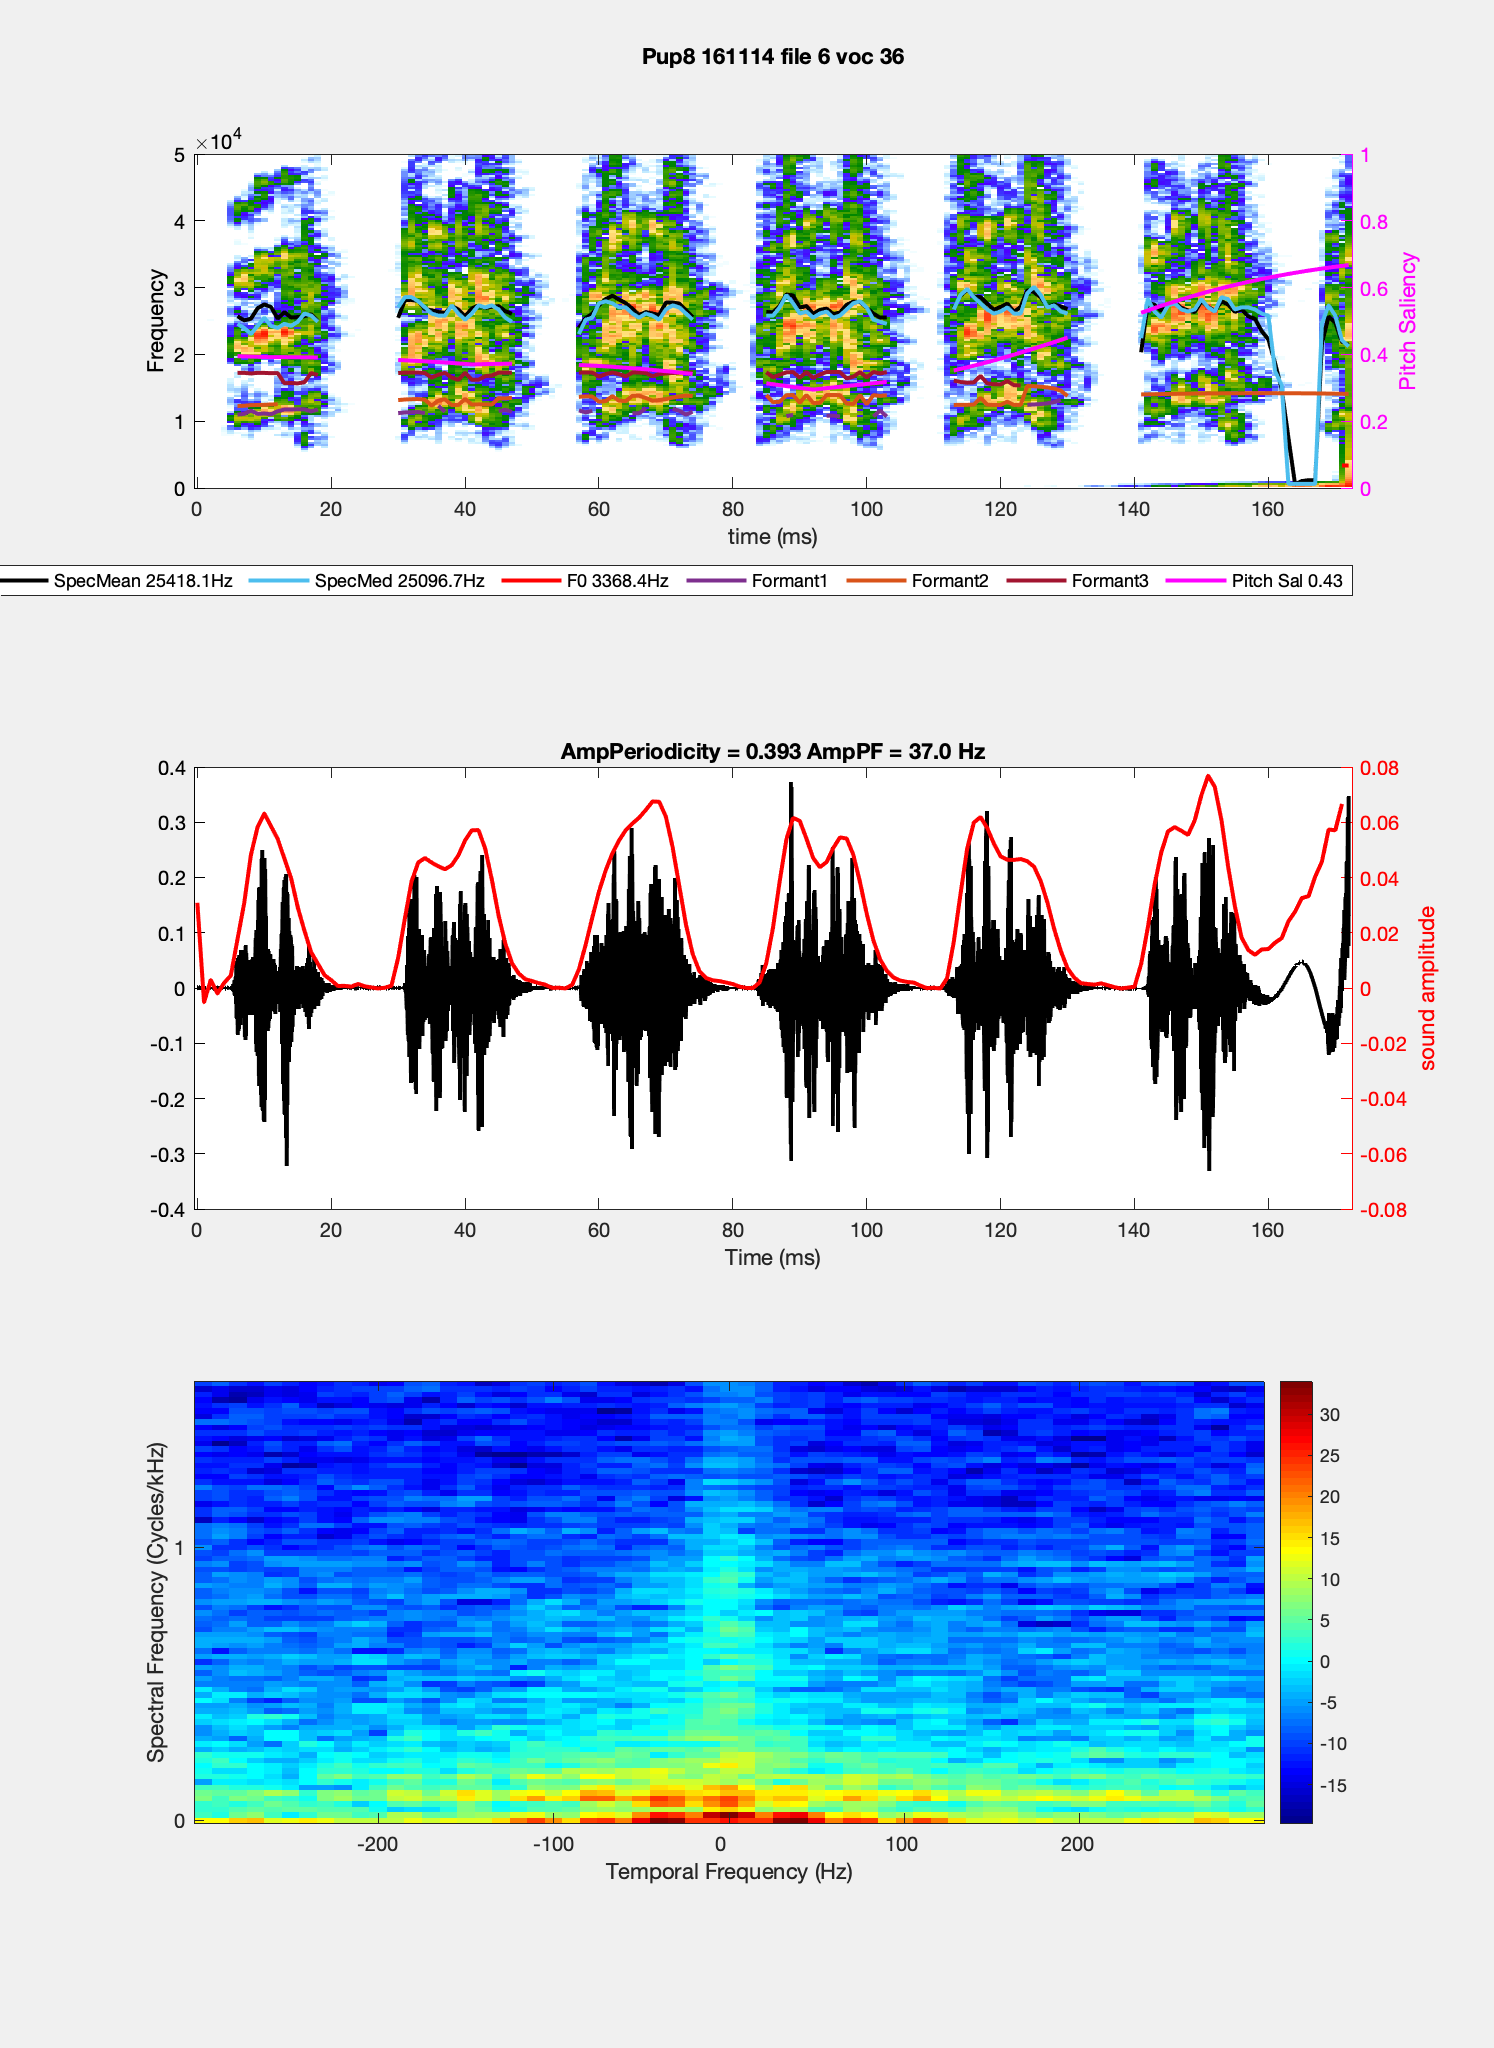

File 7/14   File 8/14   File 9/14   File 10/14   File 11/14   File 12/14   File 13/14   File 14/14   

Recording day 20161118 Pup8 (15/15)     

File 1/14   File 2/14   File 3/14   File 4/14   File 5/14   File 6/14   File 7/14   File 8/14   File 9/14   File 10/14   File 11/14   File 12/14   File 13/14   File 14/14   

64/15253 calls/triggers for this pup!

CheckAgain=1;
[z,p,k] = butter(6,[100 23500]/(FS/2),'bandpass');
sos_raw_band = zp2sos(z,p,k);
CallInd = cell(1, length(Pups));
CallCounter = zeros(1,length(Pups));
TriggerCounter = zeros(1,length(Pups));
for pp=1:length(Pups)
    PupID_local = Pups(pp);
    % total number of triggers for this pup
    NTrig = sum((IDDates_all>(PupID_local*1000000 + 160000)).*(IDDates_all<(PupID_local*1000000 + 170000)));
    Proportion_manual = Nsamples/NTrig;
    UIDate_pup = find((UIDDate>(PupID_local*1000000 + 160000)).*(UIDDate<(PupID_local*1000000 + 170000)));
    NDates = length(UIDate_pup);
    DatesCured = UIDDate(UIDate_pup(sort([2 1:round(1/Proportion_manual):NDates])));
    fprintf(1, "%d dates were cured for this pup #%d\n", length(DatesCured), PupID_local);

    % Loop through dates count data
    StartDate=1;
    CallInd{pp} = cell(length(DatesCured),1);
    for dd=StartDate:length(DatesCured)
        Date2cure_str = num2str(DatesCured(dd));
        fprintf(1, 'Recording day 20%s Pup%d (%d/%d)     ', Date2cure_str(2:end), PupID_local, dd, length(DatesCured))
        FilesName = dir(fullfile(Path2Data, ['20' Date2cure_str(2:end)], sprintf('%s_%s_VocExtractData*', Date2cure_str(2:end), repmat(Date2cure_str(1),1,4))));
        CallInd{pp}{dd} = cell(length(FilesName),1);
        for ff=1:length(FilesName)
            fprintf(1, "File %d/%d   ", ff, length(FilesName))
            DataFileName = fullfile(FilesName(ff).folder, FilesName(ff).name);
            load(DataFileName, "BioSound_all")
            CallCounter(pp) = CallCounter(pp) + sum(~cellfun('isempty', BioSound_all));
            TriggerCounter(pp) = TriggerCounter(pp) + length(BioSound_all);
            if CheckAgain
                IndVoc = find(~cellfun('isempty', BioSound_all));
%                 GoodCall = nan(length(IndVoc),1);
                PupCall = nan(length(IndVoc),1);
                for ii=1:length(IndVoc)
                    figure(1); clf; set(gcf, 'visible','on');
                    plotBiosound(BioSound_all{IndVoc(ii)}, F_high);
                    suplabel(sprintf('Pup%d %s file %d voc %d', PupID_local, Date2cure_str(2:end),ff, IndVoc(ii)),'t');
                    SoundFilt = filtfilt(sos_raw_band,1,BioSound_all{IndVoc(ii)}.sound);
                    % resample at 48kHz readble by computer
                    SampleMic = resample((SoundFilt - mean(SoundFilt))/(std(SoundFilt)/VolFactorMic),FS/4,FS);
                    PLAY = audioplayer(SampleMic, FS/4);
%                     while GoodCall(ii)~=0 && GoodCall(ii)~=1
%                         play(PLAY)
%                         GoodCall(ii) = input('Is a good call?');
%                     end
                    while PupCall(ii)~=0 && PupCall(ii)~=1
                        play(PLAY)
                        PupCall(ii) = input('Is a good call?');
                    end
                end
%                 CallInd{pp}{dd}{ff} = IndVoc(logical(GoodCall));
%                 GoodCalls = IndVoc(logical(GoodCall));
%                 save(DataFileName, "GoodCalls", '-append')
%                 clear GoodCalls
                CallInd{pp}{dd}{ff} = IndVoc(logical(PupCall));
                PupCalls = IndVoc(logical(PupCall));
                save(DataFileName, "PupCalls", '-append')
                clear PupCalls
            end
            clear BioSound_all
        end
    end
    fprintf(1, '\n%d/%d calls/triggers for this pup!', CallCounter(pp), TriggerCounter(pp))
end

fprintf(1,"\n\n*** CONSTRUCTING TABLE *** \n")



*** CONSTRUCTING TABLE *** 


Sz = [sum(CallCounter) 9];
VarTypes = {'double','double','double','double','double', 'double','double', 'double', 'double'};
VocTable = table('Size',Sz,'VariableTypes', VarTypes,'VariableNames',{'PupID', 'Days', 'Time','Deaf', 'Isolation Call', 'Pitch Saliency', 'Pitch', 'Q1', 'Max Pitch Saliency'});
CallCount = 0;
% Gather data
for pp=1:length(Pups)
    PupID_local = Pups(pp);
    % total number of triggers for this pup
    NTrig = sum((IDDates_all>(PupID_local*1000000 + 160000)).*(IDDates_all<(PupID_local*1000000 + 170000)));
    Proportion_manual = Nsamples/NTrig;
    UIDate_pup = find((UIDDate>(PupID_local*1000000 + 160000)).*(UIDDate<(PupID_local*1000000 + 170000)));
    NDates = length(UIDate_pup);
    DatesCured = UIDDate(UIDate_pup(sort([2 1:round(1/Proportion_manual):NDates])));
    fprintf(1, "%d dates were cured for this pup #%d\n", length(DatesCured), PupID_local);

    % Loop through dates gather data
    StartDate=1;
    for dd=StartDate:length(DatesCured)
        Date2cure_str = num2str(DatesCured(dd));
        fprintf(1, 'Recording day 20%s Pup%d (%d/%d)\n', Date2cure_str(2:end), PupID_local, dd, length(DatesCured))
        FilesName = dir(fullfile(Path2Data, ['20' Date2cure_str(2:end)], sprintf('%s_%s_VocExtractData*', Date2cure_str(2:end), repmat(Date2cure_str(1),1,4))));
        for ff=1:length(FilesName)
            DataFileName = fullfile(FilesName(ff).folder, FilesName(ff).name);
            load(DataFileName, "BioSound_all","Mic_Time","GoodCalls", "PupCalls")
            IndVoc = find(~cellfun('isempty', BioSound_all));
            if sum(ismember(GoodCalls, IndVoc)) ~= length(GoodCalls)
                keyboard
            end
            NVocLocal = length(GoodCalls);
            for vv=1:length(GoodCalls)
                CallCount = CallCount+1;
                Day_local = str2double(Date2cure_str((end-1):end));
                Month_local = str2double(Date2cure_str((end-3):end-2));
                if Month_local == 9
                    Day_local = Day_local + 31;
                elseif Month_local == 10
                    Day_local = Day_local + 31 +30;
                elseif Month_local == 11
                    Day_local = Day_local + 31 +30 +31;
                end
                if ismember(GoodCalls(vv),PupCalls) %This is an isolation call
                    VocTable(CallCount,:) = {PupID_local, Day_local - DOD2(pp), str2double(Mic_Time.(sprintf('Logger%d',PupID_local)){GoodCalls(vv)}), Day_local>DOD2(pp), 1, BioSound_all{GoodCalls(vv)}.MeanSal, BioSound_all{GoodCalls(vv)}.MeanF0,BioSound_all{GoodCalls(vv)}.MeanQ1t, max(BioSound_all{GoodCalls(vv)}.sal)};
                else %This is NOT an isolation call
                    VocTable(CallCount,:) = {PupID_local, Day_local - DOD2(pp), str2double(Mic_Time.(sprintf('Logger%d',PupID_local)){GoodCalls(vv)}), Day_local>DOD2(pp), 0, BioSound_all{GoodCalls(vv)}.MeanSal, BioSound_all{GoodCalls(vv)}.MeanF0,BioSound_all{GoodCalls(vv)}.MeanQ1t, max(BioSound_all{GoodCalls(vv)}.sal)};
                end
            end
        end
    end
end

9 dates were cured for this pup #4


Recording day 20160818 Pup4 (1/9)
Recording day 20160819 Pup4 (2/9)
Recording day 20160826 Pup4 (3/9)
Recording day 20160903 Pup4 (4/9)
Recording day 20160911 Pup4 (5/9)
Recording day 20160919 Pup4 (6/9)
Recording day 20160927 Pup4 (7/9)
Recording day 20161005 Pup4 (8/9)
Recording day 20161013 Pup4 (9/9)


16 dates were cured for this pup #6


Recording day 20160914 Pup6 (1/16)
Recording day 20160915 Pup6 (2/16)
Recording day 20160918 Pup6 (3/16)
Recording day 20160922 Pup6 (4/16)
Recording day 20160926 Pup6 (5/16)
Recording day 20160930 Pup6 (6/16)
Recording day 20161004 Pup6 (7/16)
Recording day 20161008 Pup6 (8/16)
Recording day 20161012 Pup6 (9/16)
Recording day 20161016 Pup6 (10/16)
Recording day 20161020 Pup6 (11/16)
Recording day 20161024 Pup6 (12/16)
Recording day 20161028 Pup6 (13/16)
Recording day 20161101 Pup6 (14/16)
Recording day 20161105 Pup6 (15/16)
Recording day 20161109 Pup6 (16/16)


31 dates were cured for this pup #7


Recording day 20160923 Pup7 (1/31)
Recording day 20160924 Pup7 (2/31)
Recording day 20160925 Pup7 (3/31)
Recording day 20160927 Pup7 (4/31)
Recording day 20160929 Pup7 (5/31)
Recording day 20161001 Pup7 (6/31)
Recording day 20161003 Pup7 (7/31)
Recording day 20161005 Pup7 (8/31)
Recording day 20161007 Pup7 (9/31)
Recording day 20161009 Pup7 (10/31)
Recording day 20161011 Pup7 (11/31)
Recording day 20161013 Pup7 (12/31)
Recording day 20161015 Pup7 (13/31)
Recording day 20161017 Pup7 (14/31)
Recording day 20161019 Pup7 (15/31)
Recording day 20161021 Pup7 (16/31)
Recording day 20161023 Pup7 (17/31)
Recording day 20161025 Pup7 (18/31)
Recording day 20161027 Pup7 (19/31)
Recording day 20161029 Pup7 (20/31)
Recording day 20161031 Pup7 (21/31)
Recording day 20161102 Pup7 (22/31)
Recording day 20161104 Pup7 (23/31)
Recording day 20161106 Pup7 (24/31)
Recording day 20161108 Pup7 (25/31)
Recording day 20161110 Pup7 (26/31)
Recording day 20161112 Pup7 (27/31)
Recording day 20161114 Pup7 (28/31)
R

15 dates were cured for this pup #8


Recording day 20160927 Pup8 (1/15)
Recording day 20160928 Pup8 (2/15)
Recording day 20161001 Pup8 (3/15)
Recording day 20161005 Pup8 (4/15)
Recording day 20161009 Pup8 (5/15)
Recording day 20161013 Pup8 (6/15)
Recording day 20161017 Pup8 (7/15)
Recording day 20161021 Pup8 (8/15)
Recording day 20161025 Pup8 (9/15)
Recording day 20161029 Pup8 (10/15)
Recording day 20161102 Pup8 (11/15)
Recording day 20161106 Pup8 (12/15)
Recording day 20161110 Pup8 (13/15)
Recording day 20161114 Pup8 (14/15)
Recording day 20161118 Pup8 (15/15)


VocTable = VocTable(1:CallCount,:);

fprintf(1,"\n\n*** Figures *** \n")



*** Figures *** 


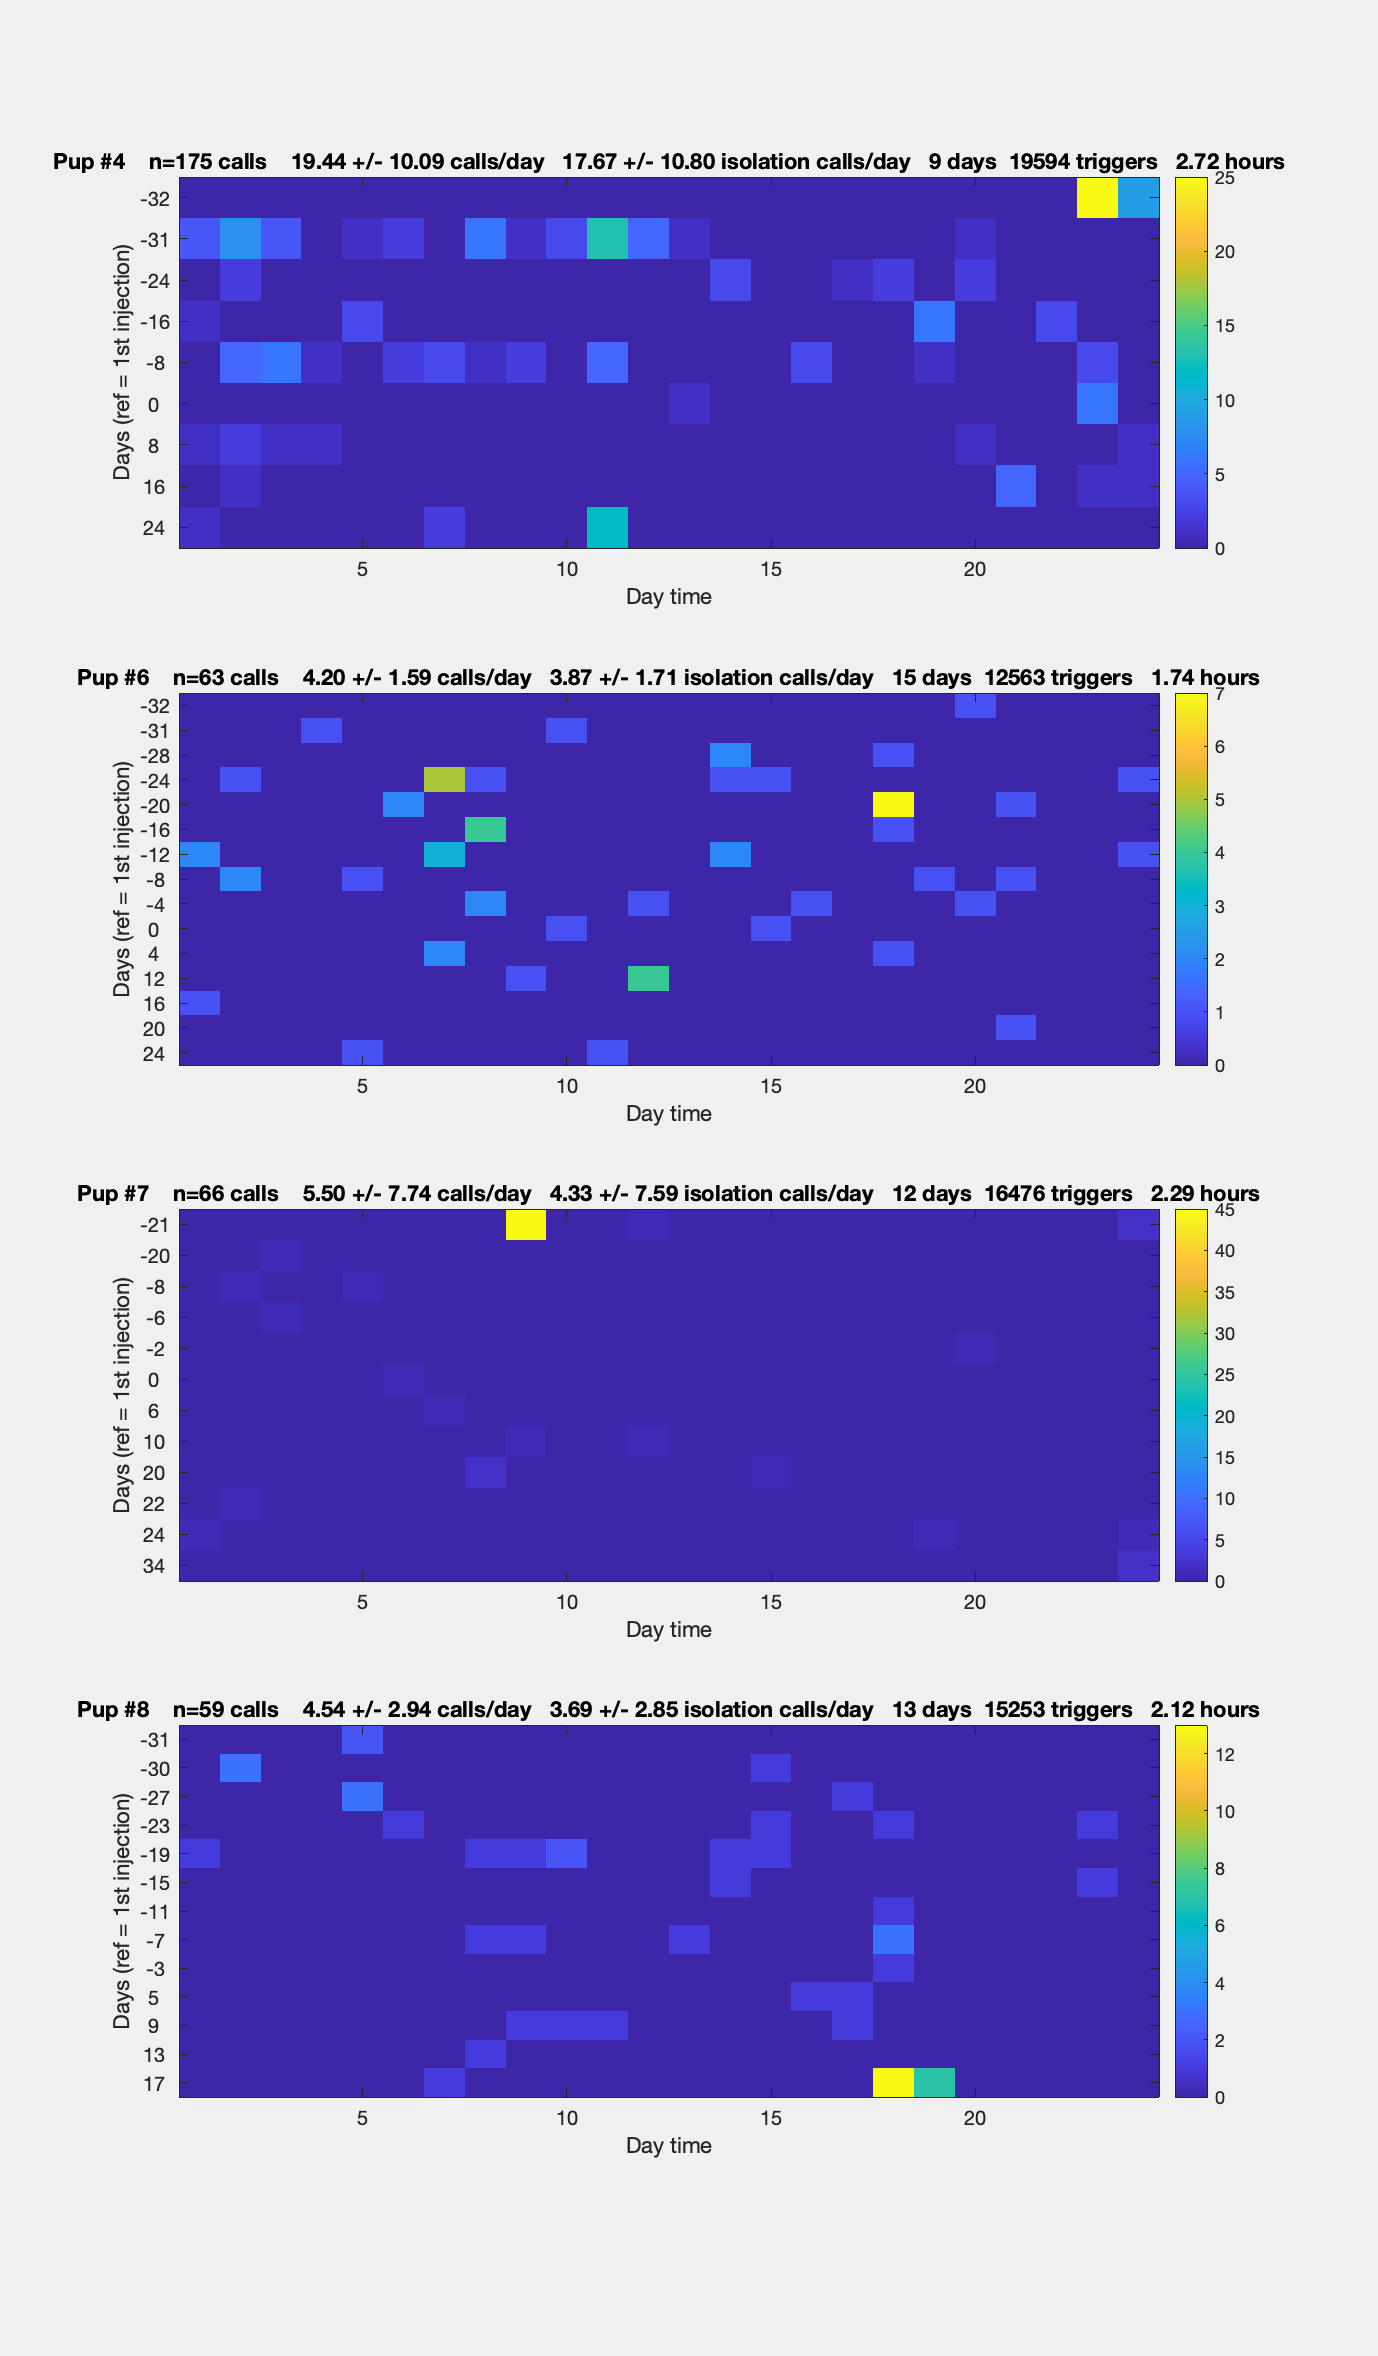

Pup #4    n=175 calls    1.78 +/- 2.60 other calls/day   17.67 +/- 10.80 isolation calls/day   9 days  19594 triggers   2.72 hours
Pup #6    n=63 calls    0.33 +/- 0.32 other calls/day   3.87 +/- 1.71 isolation calls/day   15 days  12563 triggers   1.74 hours
Pup #7    n=66 calls    1.17 +/- 0.54 other calls/day   4.33 +/- 7.59 isolation calls/day   12 days  16476 triggers   2.29 hours


Pup #8    n=59 calls    0.85 +/- 0.63 other calls/day   3.69 +/- 2.85 isolation calls/day   13 days  15253 triggers   2.12 hours


% plot one matrix of number of calls per pup
figure(2); clf; set(gcf, 'visible','on');
NumVocTable = table('Size',[49 6],'VariableTypes', VarTypes(1:6),'VariableNames',{'PupID', 'Days', 'NumVoc', 'NumVocHigh','NumVocLow', 'NumIsoCalls'});
DayCount = 0;
for pp=1:length(Pups)
    PupInd = find(VocTable.PupID==Pups(pp));
    UDates = unique(VocTable.Days(PupInd));
    NbCalls = nan(length(UDates), 24);
    NbIsoCalls = nan(length(UDates), 24);
    for dd=1:length(UDates)
        DateInd = find(VocTable.Days==UDates(dd));
        PpDdInd = intersect(PupInd, DateInd);
        for hh=1:24
            NbCalls(dd,hh) = sum((VocTable.Time(PpDdInd)>((hh-1)*10000)) .* (VocTable.Time(PpDdInd)<((hh)*10000)));
            NbIsoCalls(dd,hh) = sum((VocTable.Time(PpDdInd)>((hh-1)*10000)) .* (VocTable.Time(PpDdInd)<((hh)*10000)).* (VocTable.("Isolation Call")(PpDdInd)));
        end
        DayCount = DayCount + 1;
        NumVocTable(DayCount,:) = {Pups(pp), UDates(dd), sum(NbCalls(dd,:)), sum(VocTable.Pitch(PpDdInd)>10000), sum(VocTable.Pitch(PpDdInd)<10000), sum(VocTable.("Isolation Call")(PpDdInd))};
    end
    subplot(4,1,pp)
    imagesc(NbCalls)
    title(sprintf('Pup #%d    n=%d calls    %.2f +/- %.2f calls/day   %.2f +/- %.2f isolation calls/day   %d days  %d triggers   %.2f hours', Pups(pp), sum(sum(NbCalls)), mean(sum(NbCalls,2)), 2.*std(sum(NbCalls,2)).*(size(NbCalls,1))^-0.5,mean(sum(NbIsoCalls,2)), 2.*std(sum(NbIsoCalls,2)).*(size(NbIsoCalls,1))^-0.5, size(NbCalls,1), TriggerCounter(pp), TriggerCounter(pp)/2/60/60))
    set(gca, 'YTick', 1:length(UDates),'YTickLabel', UDates)
    ylabel('Days (ref = 1st injection)')
    xlabel('Day time')
    colorbar()
    fprintf(1,'Pup #%d    n=%d calls    %.2f +/- %.2f other calls/day   %.2f +/- %.2f isolation calls/day   %d days  %d triggers   %.2f hours\n',Pups(pp), sum(sum(NbCalls)), mean(sum(NbCalls-NbIsoCalls,2)), 2.*std(sum(NbCalls-NbIsoCalls,2)).*(size(NbCalls-NbIsoCalls,1))^-0.5,mean(sum(NbIsoCalls,2)), 2.*std(sum(NbIsoCalls,2)).*(size(NbIsoCalls,1))^-0.5, size(NbCalls,1), TriggerCounter(pp), TriggerCounter(pp)/2/60/60)
%     set(gca, 'CLim',[0 15])
end

NumVocTable

NumVocTable = 49×6 table
    PupID    Days    NumVoc    NumVocHigh    NumVocLow    NumIsoCalls
    _____    ____    ______    __________    _________    ___________

      4      -32       34          32            0            34     
      4      -31       49          44            3            49     
      4      -24       10           8            0             8     
      4      -16       13          12            1            13     
      4       -8       32          28            2            31     
      4        0        7           6            0             6     
      4        8        7           3            2             7     
      4       16        8           6            1             8     
      4       24       15          13            0             3     


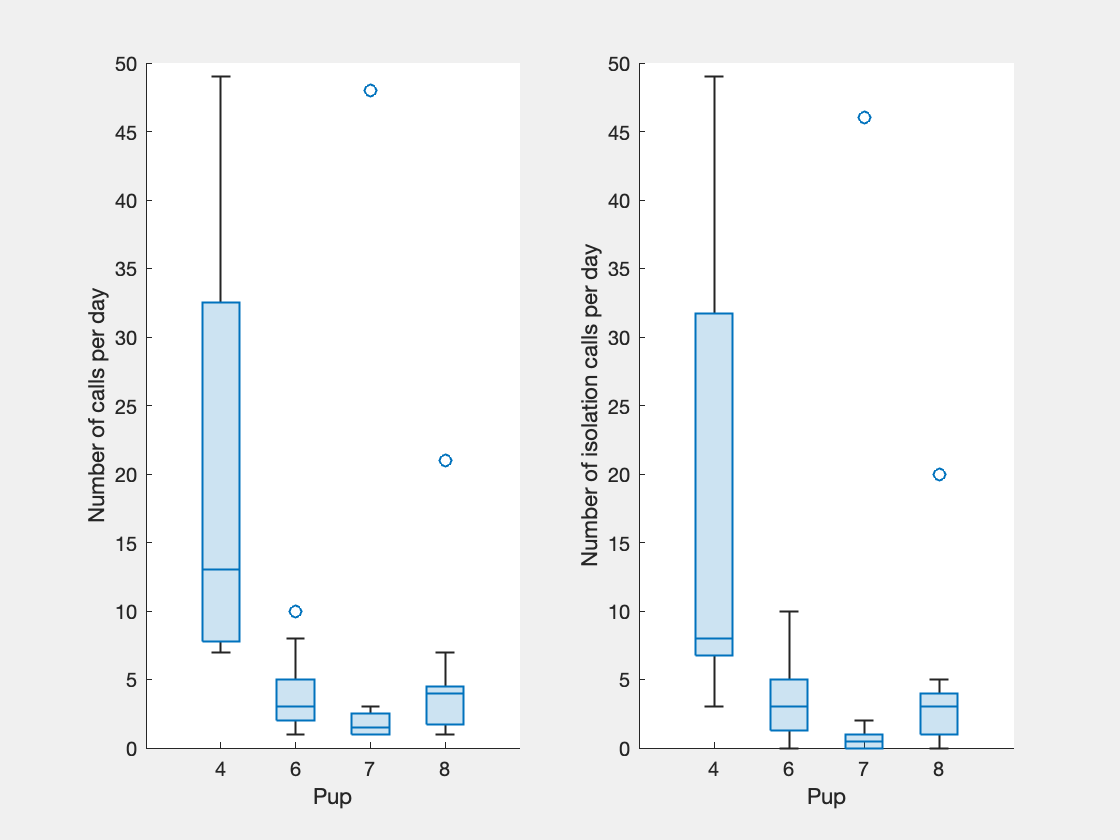

figure(3);clf;  set(gcf, 'visible','on'); subplot(1,2,1);  boxchart(categorical(NumVocTable.PupID), NumVocTable.NumVoc)
xlabel('Pup')
ylabel('Number of calls per day')
subplot(1,2,2); boxchart(categorical(NumVocTable.PupID), NumVocTable.NumIsoCalls)
xlabel('Pup')
ylabel('Number of isolation calls per day')

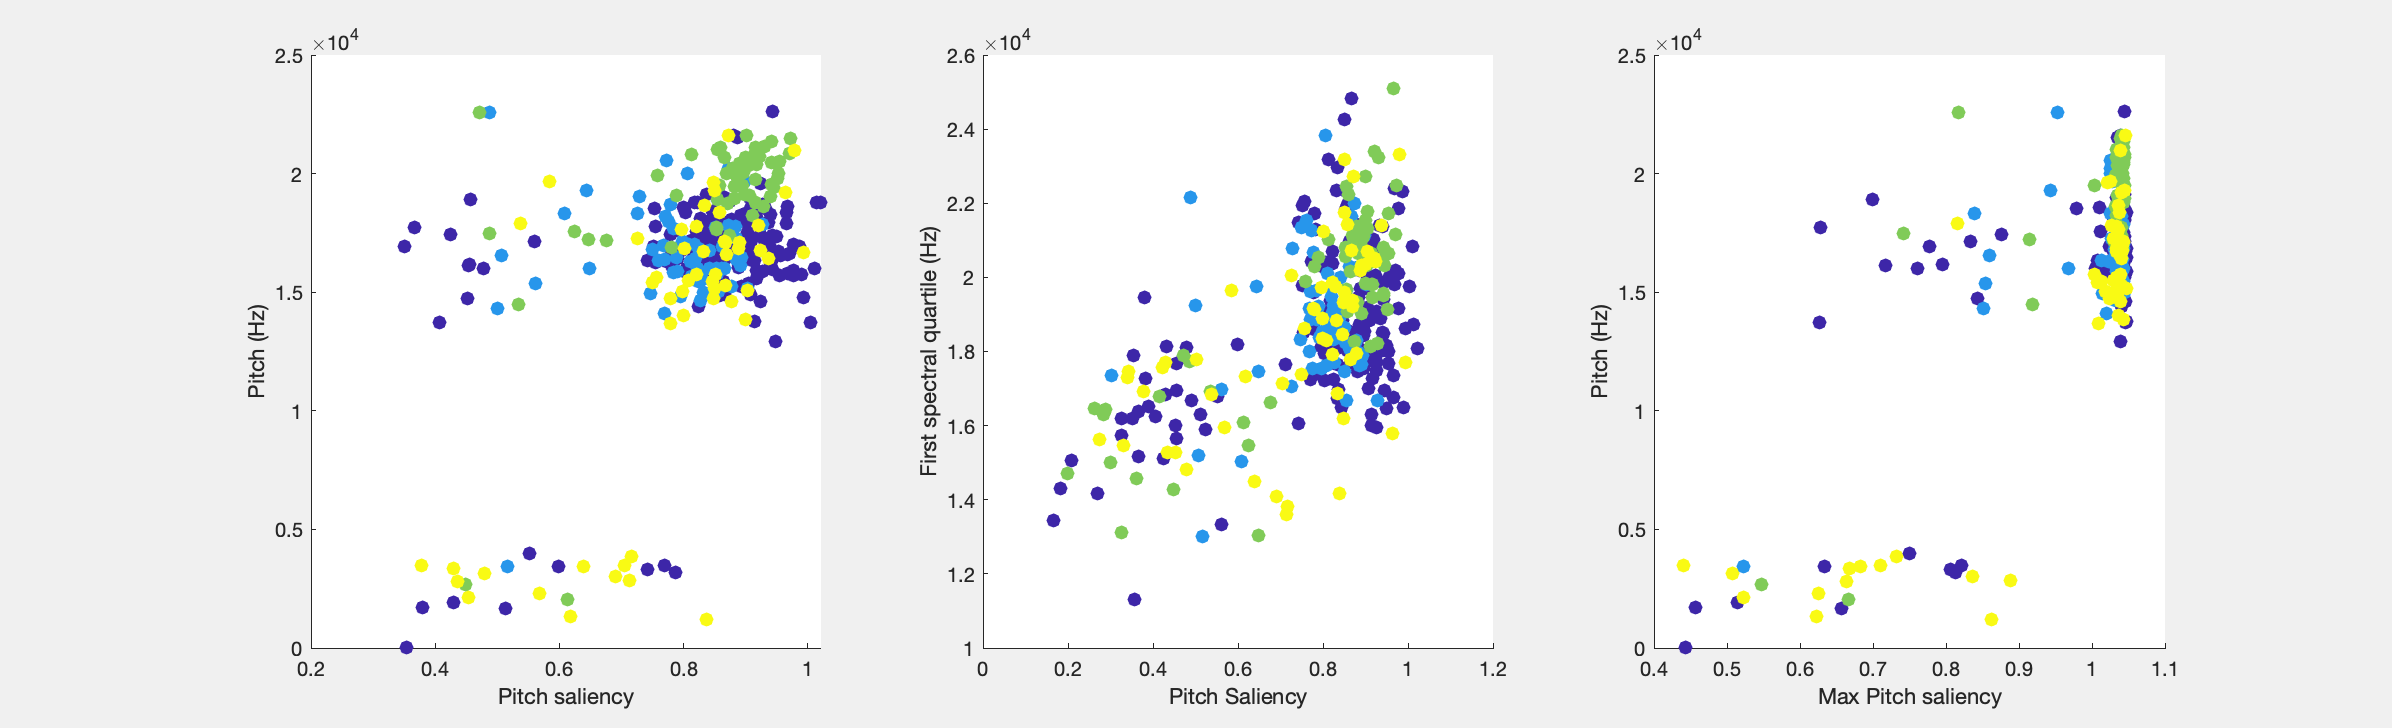

figure(4); clf; set(gcf, 'visible','on');
subplot(1,3,1)
scatter(VocTable.("Pitch Saliency"), VocTable.Pitch, 50, categorical(VocTable.PupID), 'filled')
ylabel('Pitch (Hz)')
xlabel('Pitch saliency')
subplot(1,3,2)
scatter(VocTable.("Pitch Saliency"), VocTable.("Q1"), 50, categorical(VocTable.PupID), 'filled')
ylabel('First spectral quartile (Hz)')
xlabel('Pitch Saliency')
subplot(1,3,3)
scatter(VocTable.("Max Pitch Saliency"), VocTable.Pitch, 50, categorical(VocTable.PupID), 'filled')
ylabel('Pitch (Hz)')
xlabel('Max Pitch saliency')

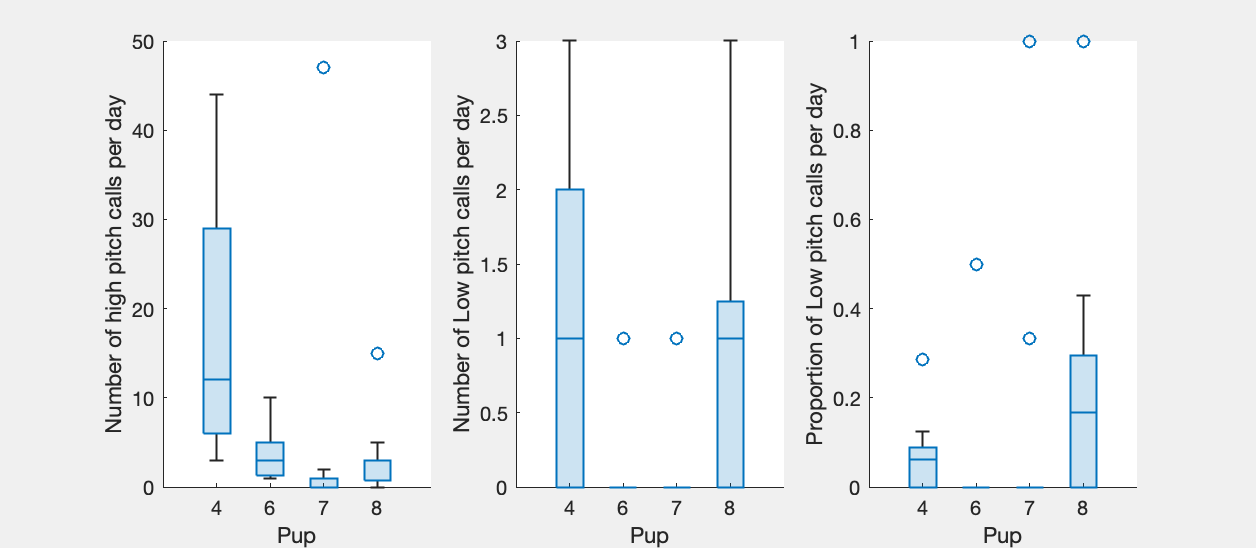

figure(5); clf; set(gcf, 'visible','on');
subplot(1,3,1)
boxchart(categorical(NumVocTable.PupID), NumVocTable.NumVocHigh)
xlabel('Pup')
ylabel('Number of high pitch calls per day')
subplot(1,3,2)
boxchart(categorical(NumVocTable.PupID), NumVocTable.NumVocLow)
xlabel('Pup')
ylabel('Number of Low pitch calls per day')
subplot(1,3,3)
boxchart(categorical(NumVocTable.PupID), NumVocTable.NumVocLow./NumVocTable.NumVoc)
xlabel('Pup')
ylabel('Proportion of Low pitch calls per day')

For each pup look at bioacsoutic variables over time (any effect of deafening?)

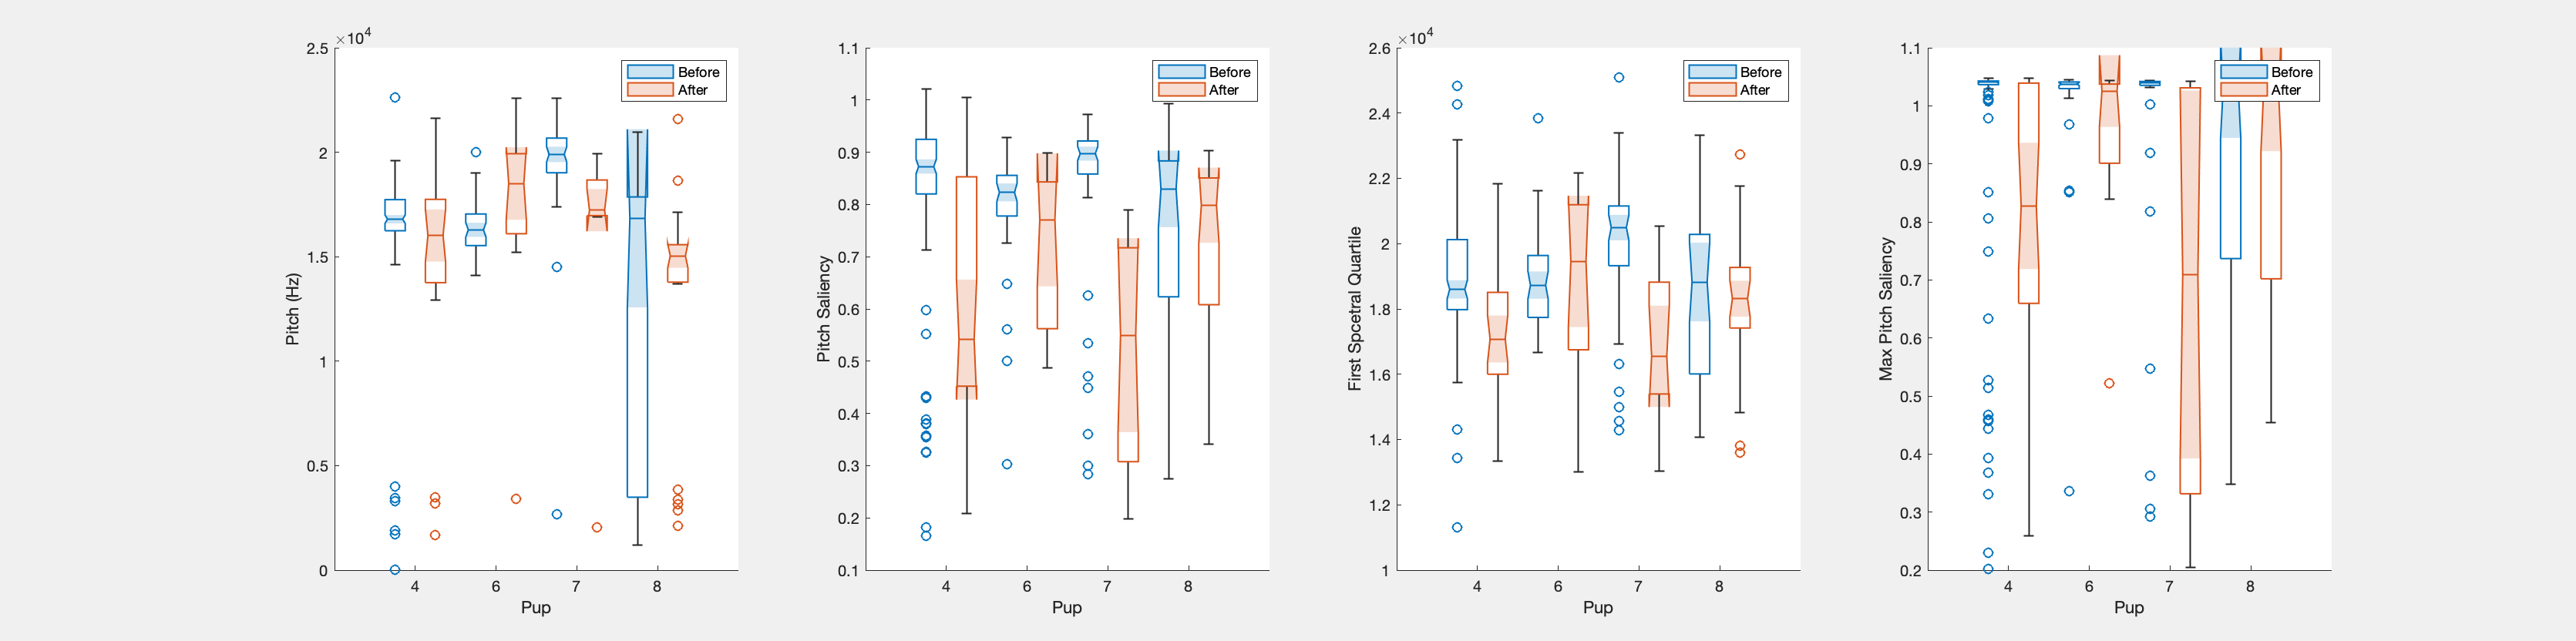

figure(6); clf; set(gcf, 'visible','on');
subplot(1,4,1)
boxchart(categorical(VocTable.PupID), VocTable.Pitch, 'GroupByColor', VocTable.Deaf, 'Notch', 'on')
xlabel('Pup')
ylabel('Pitch (Hz)')
legend({'Before', 'After'})
subplot(1,4,2)
boxchart(categorical(VocTable.PupID), VocTable.("Pitch Saliency"), 'GroupByColor', categorical(VocTable.Deaf), 'Notch', 'on')
xlabel('Pup')
ylabel('Pitch Saliency')
legend({'Before', 'After'})
subplot(1,4,3)
boxchart(categorical(VocTable.PupID), VocTable.("Q1"), 'GroupByColor', categorical(VocTable.Deaf), 'Notch', 'on')
xlabel('Pup')
ylabel('First Spcetral Quartile')
legend({'Before', 'After'})
subplot(1,4,4)
boxchart(categorical(VocTable.PupID), VocTable.("Max Pitch Saliency"), 'GroupByColor', categorical(VocTable.Deaf), 'Notch', 'on')
xlabel('Pup')
ylabel('Max Pitch Saliency')
legend({'Before', 'After'})

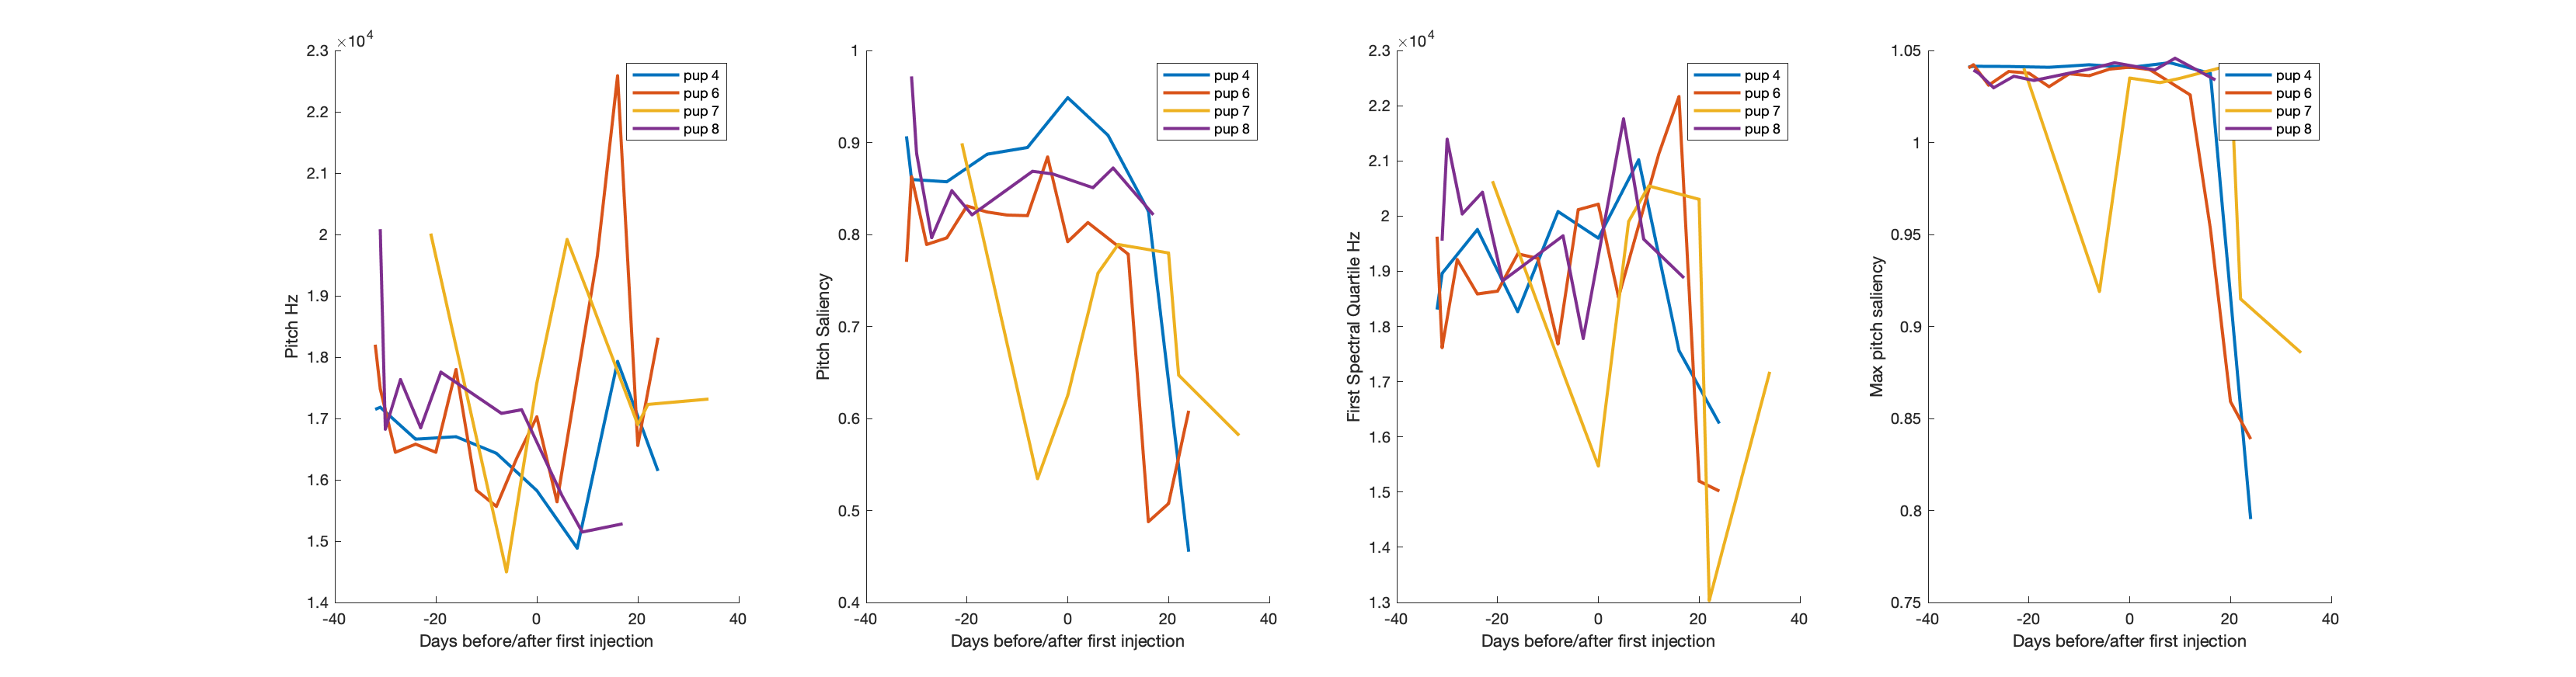

figure(7); clf; set(gcf, 'visible','on');

subplot(1,4,1)
Legend = cell(1,4);
for pp=1:length(Pups)
    IndPup = find(VocTable.PupID == Pups(pp));
    UDates = unique(VocTable.Days(IndPup));
    PitchData = size(2,length(UDates));
    for dd=1:length(UDates)
        PitchData(1,dd) = UDates(dd);
        IndvocLocal = intersect(IndPup, find(VocTable.Days==UDates(dd)));
        IndPupVoc = (VocTable.Pitch(IndvocLocal)>10000);
        PitchData(2,dd) = median(VocTable.Pitch(IndvocLocal(IndPupVoc)), 'omitnan');
        PitchData(3,dd) = 2*std(VocTable.Pitch(IndvocLocal(IndPupVoc)), 'omitnan')./(length(IndvocLocal)^0.5);
    end
    hold on
    plot(PitchData(1,~isnan(PitchData(2,:))), PitchData(2,~isnan(PitchData(2,:))), 'LineWidth',2)
    Legend{pp} = sprintf('pup %d', Pups(pp));
%     shadedErrorBar(PitchData(1,:), PitchData(2,:), PitchData(3,:))
end
legend(Legend)
hold off
xlabel('Days before/after first injection')
ylabel('Pitch Hz')

subplot(1,4,2)
Legend = cell(1,4);
for pp=1:length(Pups)
    IndPup = find(VocTable.PupID == Pups(pp));
    UDates = unique(VocTable.Days(IndPup));
    PitchSalData = size(2,length(UDates));
    for dd=1:length(UDates)
        PitchSalData(1,dd) = UDates(dd);
        IndvocLocal = intersect(IndPup, find(VocTable.Days==UDates(dd)));
        IndPupVoc = (VocTable.Pitch(IndvocLocal)>10000);
        PitchSalData(2,dd) = median(VocTable.("Pitch Saliency")(IndvocLocal(IndPupVoc)), 'omitnan');
        PitchSalData(3,dd) = 2*std(VocTable.("Pitch Saliency")(IndvocLocal(IndPupVoc)), 'omitnan')./(length(IndvocLocal)^0.5);
    end
    hold on
    plot(PitchSalData(1,~isnan(PitchSalData(2,:))), PitchSalData(2,~isnan(PitchSalData(2,:))), 'LineWidth',2)
    Legend{pp} = sprintf('pup %d', Pups(pp));
%     shadedErrorBar(PitchData(1,:), PitchData(2,:), PitchData(3,:))
end
legend(Legend)
hold off
xlabel('Days before/after first injection')
ylabel('Pitch Saliency')

subplot(1,4,3)
Legend = cell(1,4);
for pp=1:length(Pups)
    IndPup = find(VocTable.PupID == Pups(pp));
    UDates = unique(VocTable.Days(IndPup));
    Q1Data = size(2,length(UDates));
    for dd=1:length(UDates)
        Q1Data(1,dd) = UDates(dd);
        IndvocLocal = intersect(IndPup, find(VocTable.Days==UDates(dd)));
        IndPupVoc = (VocTable.Pitch(IndvocLocal)>10000);
        Q1Data(2,dd) = median(VocTable.Q1(IndvocLocal(IndPupVoc)), 'omitnan');
        Q1Data(3,dd) = 2*std(VocTable.Q1(IndvocLocal(IndPupVoc)), 'omitnan')./(length(IndvocLocal)^0.5);
    end
    hold on
    plot(Q1Data(1,~isnan(Q1Data(2,:))), Q1Data(2,~isnan(Q1Data(2,:))), 'LineWidth',2)
    Legend{pp} = sprintf('pup %d', Pups(pp));
%     shadedErrorBar(PitchData(1,:), PitchData(2,:), PitchData(3,:))
end
legend(Legend)
hold off
xlabel('Days before/after first injection')
ylabel('First Spectral Quartile Hz')

subplot(1,4,4)
Legend = cell(1,4);
for pp=1:length(Pups)
    IndPup = find(VocTable.PupID == Pups(pp));
    UDates = unique(VocTable.Days(IndPup));
    MaxSalData = size(2,length(UDates));
    for dd=1:length(UDates)
        MaxSalData(1,dd) = UDates(dd);
        IndvocLocal = intersect(IndPup, find(VocTable.Days==UDates(dd)));
        IndPupVoc = (VocTable.Pitch(IndvocLocal)>10000);
        MaxSalData(2,dd) = median(VocTable.("Max Pitch Saliency")(IndvocLocal(IndPupVoc)), 'omitnan');
        MaxSalData(3,dd) = 2*std(VocTable.("Max Pitch Saliency")(IndvocLocal(IndPupVoc)), 'omitnan')./(length(IndvocLocal)^0.5);
    end
    hold on
    plot(MaxSalData(1,~isnan(MaxSalData(2,:))), MaxSalData(2,~isnan(MaxSalData(2,:))), 'LineWidth',2)
    Legend{pp} = sprintf('pup %d', Pups(pp));
%     shadedErrorBar(PitchData(1,:), PitchData(2,:), PitchData(3,:))
end
legend(Legend)
hold off
xlabel('Days before/after first injection')
ylabel('Max pitch saliency')

Results of the effect of Kanamycin on pup isolation calls is not super convincing and I am not really trustful of the microphone quality.... so over all. best to not mention that.

Now identify the number of sequences with posterior proba>0.9 in unshifted or shifted samples

TrueVocAdultInd = cell(length(UIDDate),1);
TrueVocPupInd = cell(length(UIDDate),1);
for dd=1:3 %length(UIDDate)
    UIDDate_str = num2str(UIDDate(dd));
    PupID = num2str(UIDDate_str(1));
    fprintf(1, 'Recording day 20%s Pup%s (%d/%d)\n', UIDDate_str(2:end), PupID, dd, length(UIDDate))
    NumFilesOut = ceil(sum(IDDates_all==UIDDate(dd))/NVoc);
    FileIndices = find(IDDates_all==UIDDate(dd));
    % find the correct file with ResNet output
    ResNetDataFile_original = dir(fullfile(Path2Data, sprintf('20%s_original.csv', UIDDate_str(2:end-1))));
    ResNetDataFile_downshift = dir(fullfile(Path2Data, sprintf('20%s_downshift.csv', UIDDate_str(2:end-1))));
    if isempty(ResNetDataFile_original)
        ResNetDataFile_original = dir(fullfile(Path2Data, sprintf('20%s_original.csv', UIDDate_str(2:end-2))));
        ResNetDataFile_downshift = dir(fullfile(Path2Data, sprintf('20%s_downshift.csv', UIDDate_str(2:end-2))));
    end
    ResNetData_original = readtable(fullfile(ResNetDataFile_original.folder, ResNetDataFile_original.name), 'Delimiter',',');
    ResNetData_downshift = readtable(fullfile(ResNetDataFile_downshift.folder, ResNetDataFile_downshift.name), 'Delimiter',',');
    for ff=1:NumFilesOut
        fprintf(1, 'File of 100 voc %d/%d\n', ff, NumFilesOut)
        if ff<NumFilesOut
            NVocLocal = NVoc;
        elseif ff==NumFilesOut
            NVocLocal = length(FileIndices) - NVoc*(ff-1);
        end
        ListFiles_local = ListFiles(FileIndices((ff-1)*NVoc + (1:NVocLocal)));
        % keep only the files with at least one 100ms with a posterior proba > 0.9
        TrueVoc = nan(1,NVocLocal);
        for vv=1:NVocLocal
            [~,Name,~] = fileparts(ListFiles_local{vv});
            RowsData = logical(contains(ResNetData_original.Var1(:), sprintf('15120%s%s_%s_%d_Logger%s', UIDDate_str(2:end),UIDDate_str(2:end), repmat(PupID,1,4), ff, PupID)) .*contains(ResNetData_original.Var1(:), sprintf('_%d.mat', vv-1)));
            pVoc_original = ResNetData_original.Var3(RowsData); % all probability of a vocalization across all 100ms windows through that original sequence (adult voc)
            pVoc_downshift = ResNetData_downshift.Var3(RowsData); % all probability of a vocalization across all 100ms windows through that downshifted sequence (pup voc)
            if any(pVoc_original>0.9)
                TrueVoc(vv) = 1;
            elseif any(pVoc_downshift>0.9)
                TrueVoc(vv) = 2;
            else
                TrueVoc(vv) = 0;
            end
        end
        TrueVocAdultInd{dd} = [TrueVocAdultInd{dd} find(TrueVoc==1)];
        TrueVocPupInd{dd} = [TrueVocPupInd{dd} find(TrueVoc==2)];
        save(fullfile(Path2Data, ['20' UIDDate_str(2:end)], sprintf('%s_%s_VocExtractData%d.mat', UIDDate_str(2:end), repmat(UIDDate_str(1),1,4),ff)), "TrueVoc",'-append')
        clear TrueVoc
    end
end

Recording day 20160727 Pup4 (1/236)


File of 100 voc 1/1


Recording day 20160728 Pup4 (2/236)


File of 100 voc 1/21
File of 100 voc 2/21


Now calculate acoustic features for calls with posterior proba>0.9 in unshifted or shifted calls (only run under Matlab 2021B)

Debug = 1;
% Import biosound library
py.importlib.import_module('soundsig')

ans =   Python module with properties:

          signal: [1×1 py.module]
    detect_peaks: [1×1 py.module]
           sound: [1×1 py.module]
        timefreq: [1×1 py.module]

    <module 'soundsig' from '/Users/elie/anaconda3/lib/python3.7/site-packages/soundsig/__init__.py'>


Recording day 5/236


File of 100 voc 1/13


running Biosound... Fundest method = AC  Fund Estimation: 156.39 seconds


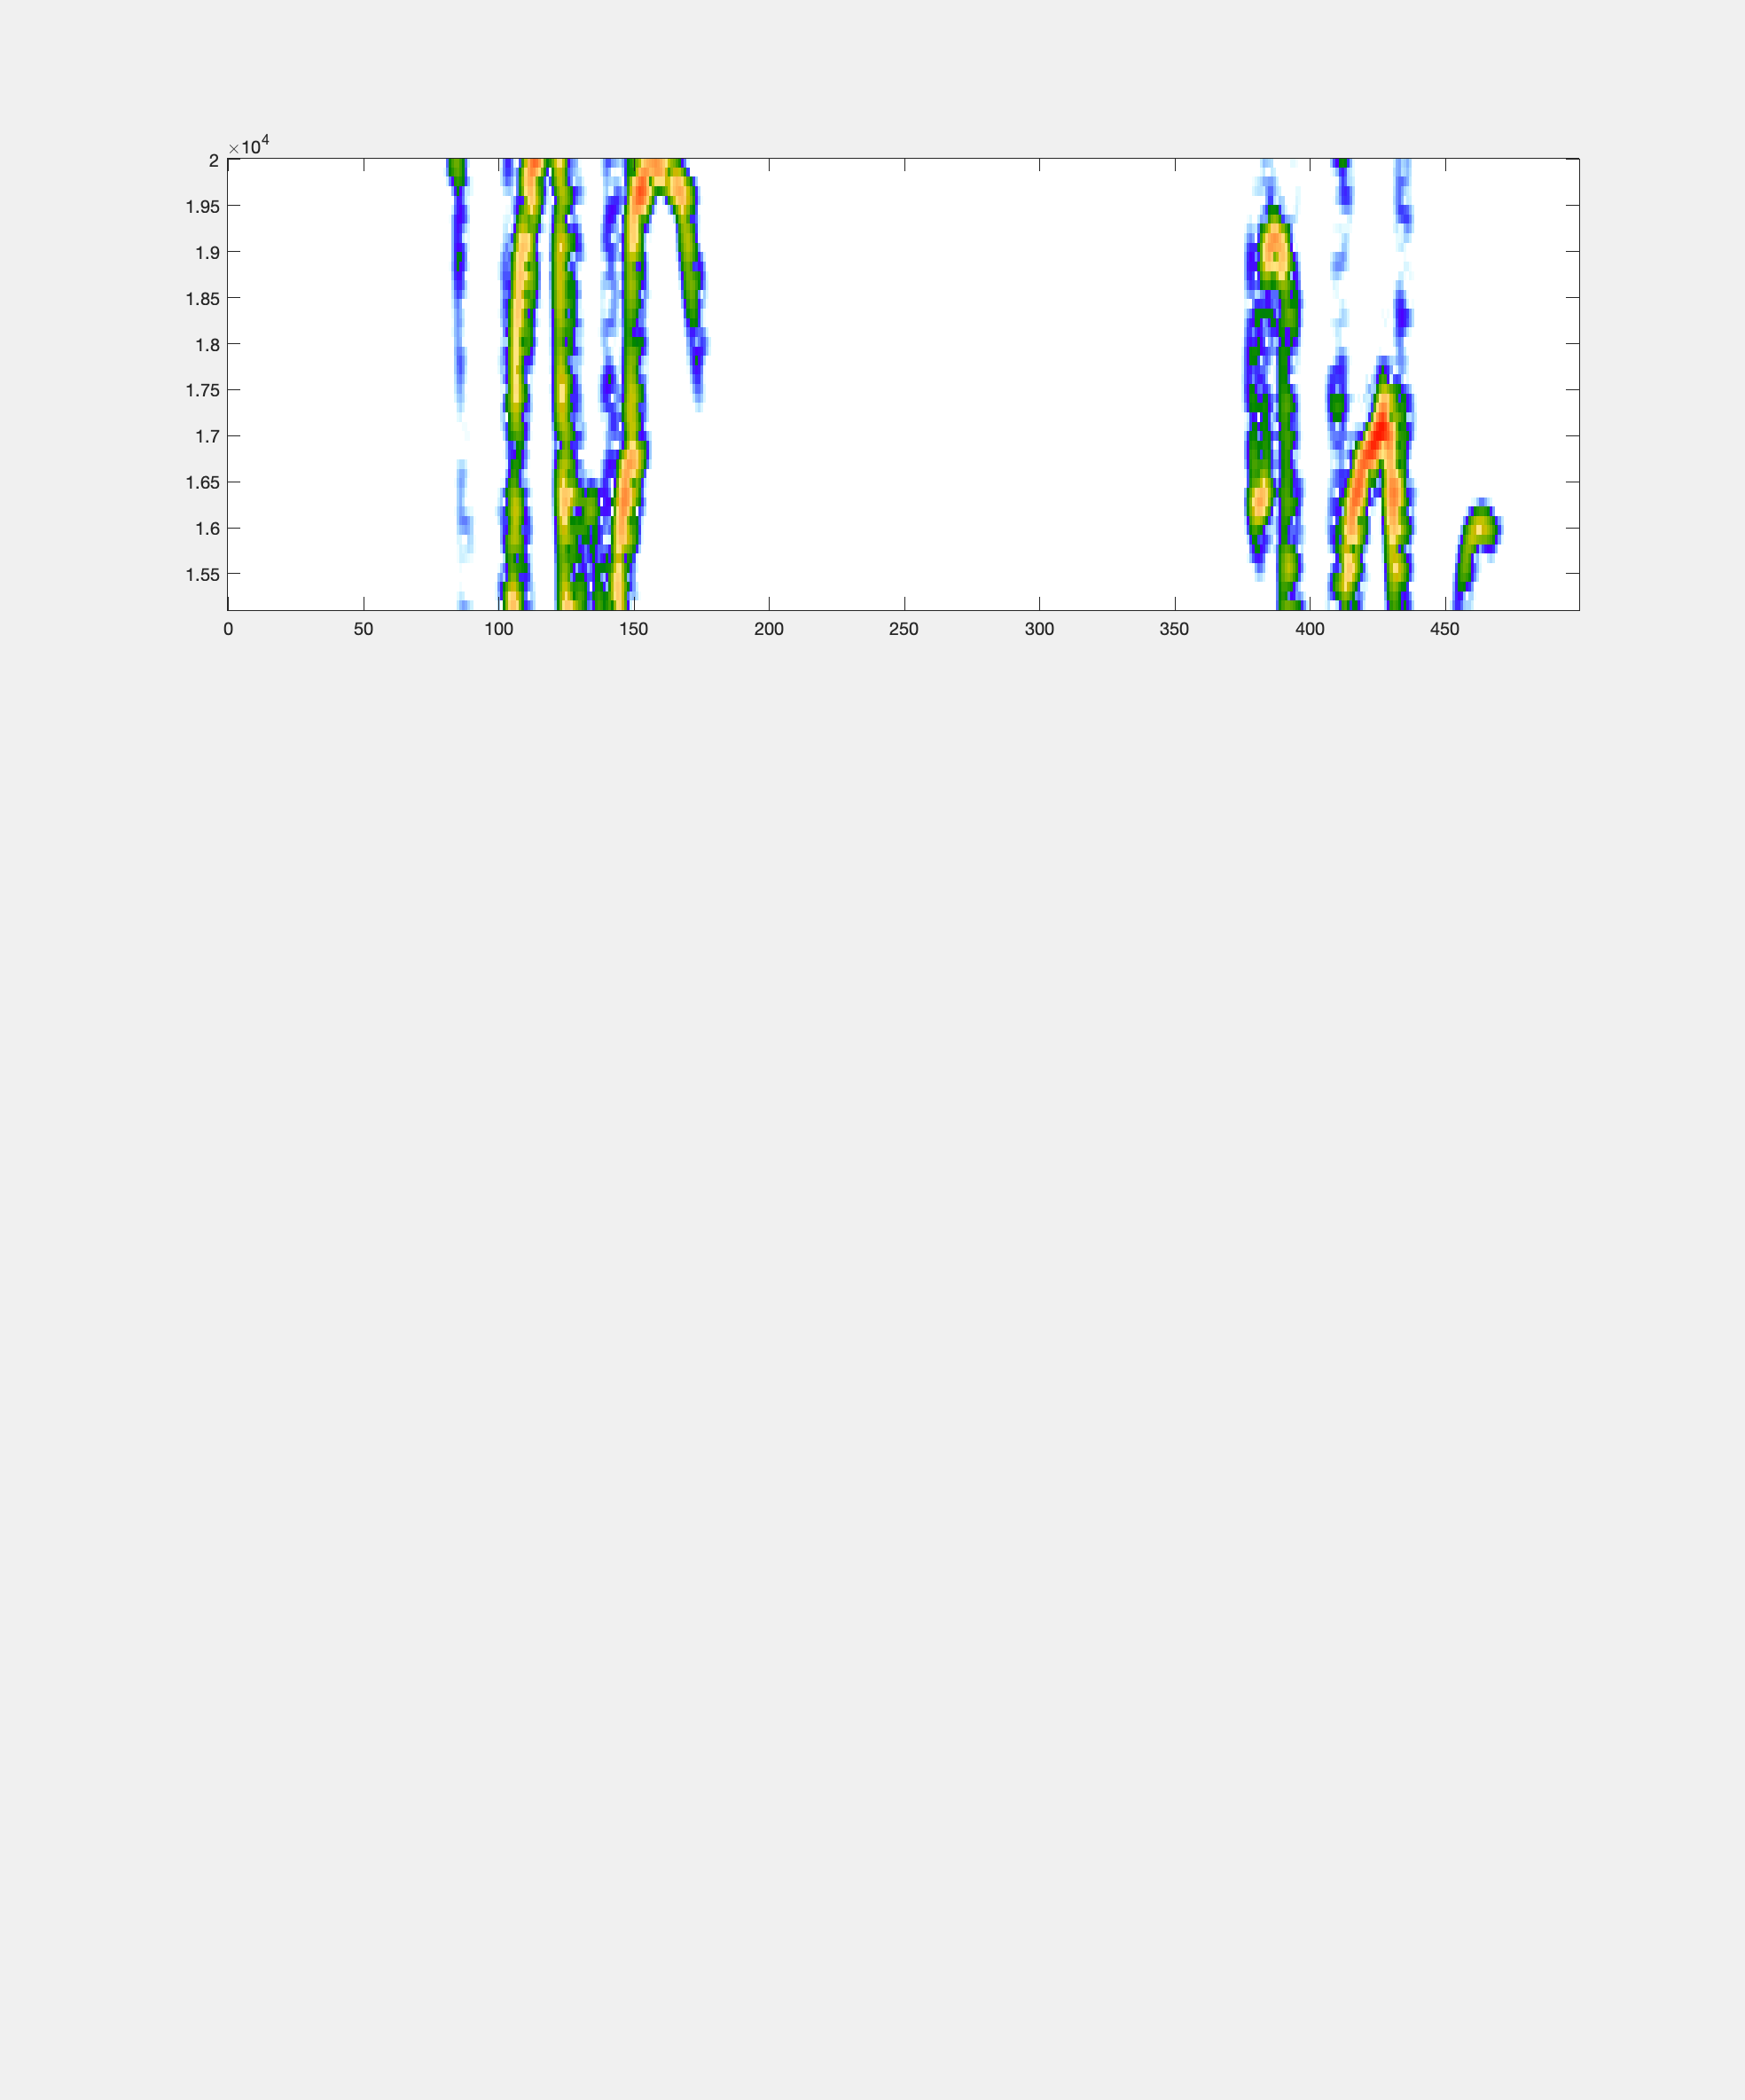

NVoc = 100; % max number of voc per file
VolFactorMic = 0.5;
FS= 192000; % Hz
DB_noise = 60;
F_high = 50000;
% design filters of raw ambient recording, bandpass 100Hz - 20kHz
[z,p,k] = butter(6,[100 50000]/(FS/2),'bandpass');
sos_raw_band = zp2sos(z,p,k);



for dd=1:length(UIDDate)
    UIDDate_str = num2str(UIDDate(dd));
    PupID = num2str(UIDDate_str(1));
    fprintf(1, 'Recording day 20%s Pup%s (%d/%d)\n', UIDDate_str(2:end), PupID, dd, length(UIDDate))
    NumFilesOut = ceil(sum(IDDates_all==UIDDate(dd))/NVoc);
    FileIndices = find(IDDates_all==UIDDate(dd));
    % find the correct file with ResNet output
    ResNetDataFile_original = dir(fullfile(Path2Data, sprintf('20%s_original.csv', UIDDate_str(2:end-1))));
    ResNetDataFile_downshift = dir(fullfile(Path2Data, sprintf('20%s_downshift.csv', UIDDate_str(2:end-1))));
    if isempty(ResNetDataFile_original)
        ResNetDataFile_original = dir(fullfile(Path2Data, sprintf('20%s_original.csv', UIDDate_str(2:end-2))));
        ResNetDataFile_downshift = dir(fullfile(Path2Data, sprintf('20%s_downshift.csv', UIDDate_str(2:end-2))));
    end
    ResNetData_original = readtable(fullfile(ResNetDataFile_original.folder, ResNetDataFile_original.name), 'Delimiter',',');
    ResNetData_downshift = readtable(fullfile(ResNetDataFile_downshift.folder, ResNetDataFile_downshift.name), 'Delimiter',',');
    for ff=1:NumFilesOut
        fprintf(1, 'File of 100 voc %d/%d\n', ff, NumFilesOut)
        if ff<NumFilesOut
            NVocLocal = NVoc;
        elseif ff==NumFilesOut
            NVocLocal = length(FileIndices) - NVoc*(ff-1);
        end
        BioSound_all = cell(NVocLocal,1);
        ListFiles_local = ListFiles(FileIndices((ff-1)*NVoc + (1:NVocLocal)));
        % keep only the files with at least one 100ms with a posterior proba > 0.9
        TrueVoc = nan(1,NVocLocal);
        for vv=1:NVocLocal
            [~,Name,~] = fileparts(ListFiles_local{vv});
            RowsData = logical(contains(ResNetData_original.Var1(:), sprintf('15120%s%s%s_Logger%s', UIDDate_str(2:end), Name(1:12), Name(end), PupID)) .*contains(ResNetData.Var1(:), sprintf('_%d.mat', vv-1)));
            pVoc_original = ResNetData_original.Var3(RowsData); % all probability of a vocalization across all 100ms windows through that original sequence (adult voc)
            pVoc_downshift = ResNetData_downshift.Var3(RowsData); % all probability of a vocalization across all 100ms windows through that downshifted sequence (pup voc)
            if any(pVoc_original>0.9)
                TrueVoc(vv) = 1;
            elseif any(pVoc_downshift>0.9)
                TrueVoc(vv) = 2;
            else
                TrueVoc(vv) = 0;
            end
        end
        TrueVocInd = find(TrueVoc);
        for vvtrue=1:length(TrueVocInd)
            vv=TrueVocInd(vvtrue);
            Sound = load(ListFiles_local{vv});
            [~,NameIn,~]=fileparts(ListFiles_local{vv});
            IndT = strfind(NameIn,'T');
            Time_voc = NameIn(IndT + (1:6));
            if Sound.fs~=FS
                warning('the extract does not have the expected sampling frequency\n')
                
            end
            % filter to 50kHz
            SoundFilt = filtfilt(sos_raw_band,1,Sound.recsGroup);
            % Calculate Biosound features
            BioSoundObj = runBiosound(SoundFilt, FS, F_high);
            if Debug
                figure(1); clf; set(gcf, 'visible','on');
                plotBiosound(BioSoundObj, F_high);
                suplabel(sprintf('Pup%s %s %s voc %d/%d', PupID, UIDDate_str(2:end),Time_voc,(ff-1)*NVoc + vv, length(FileIndices)),'t');
            end
            %save
            BioSound_all{vv} = BioSoundObj;
        end
        BioSound_all.(sprintf('Logger%s',PupID)) = BioSound_all;
        save(fullfile(Path2Data, ['20' UIDDate_str(2:end)], sprintf('%s_%s_VocExtractData%d.mat', UIDDate_str(2:end), repmat(UIDDate_str(1),1,4),ff)), "BioSound_all",'-append')
        clear BioSound_all
    end
end

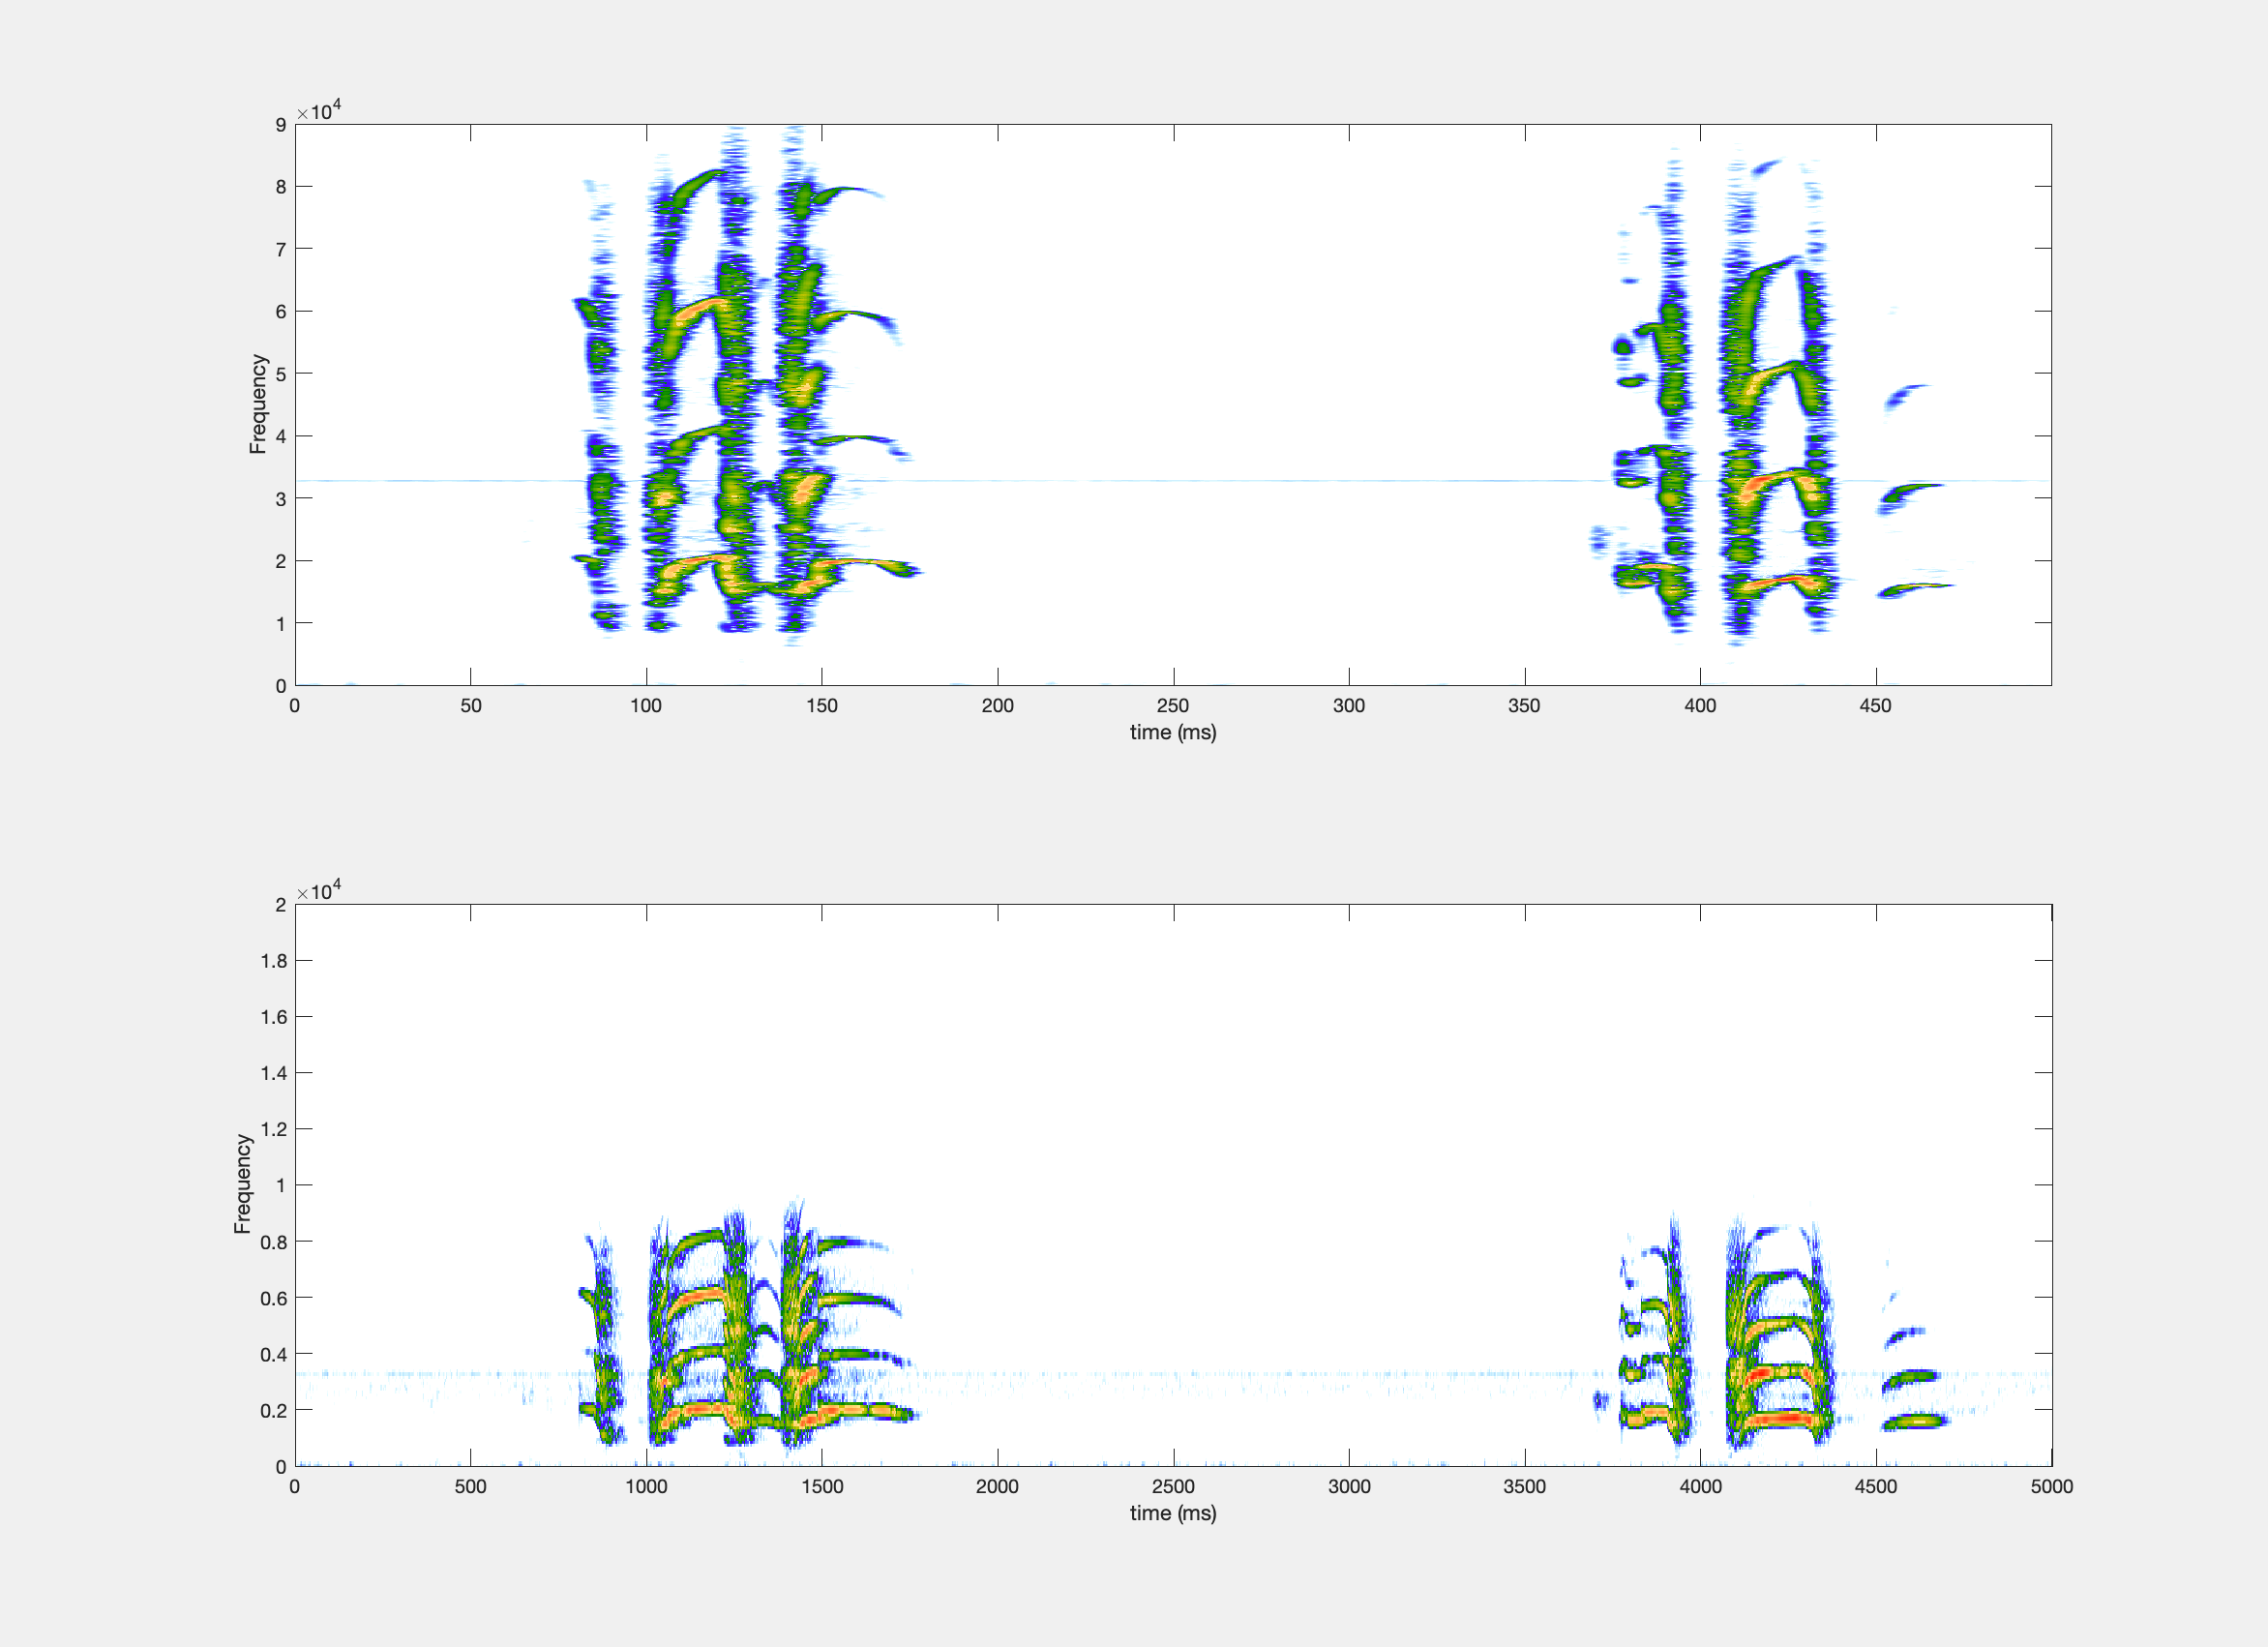

% High pitch pup call
Sound_file = '/Volumes/server_home-1/users/old lab members/Sandra/Lesion/Lesionrecordings/Lesion_Groups/Group4/Group4_20160819/Group4_20160819T000514_C_Group_Variation_0000_0001_0000.mat';
Sound = load(Sound_file);
% calculate spectrogram and plot shifting the SR by 10
figure(2); set(gcf,'Visible','on'); clf;
subplot(2,1,1)
[~] = spec_only_bats(Sound.recsGroup, Sound.fs, DB_noise, 90000);
subplot(2,1,2)
[~] = spec_only_bats(Sound.recsGroup, FS/10, DB_noise, 20000);

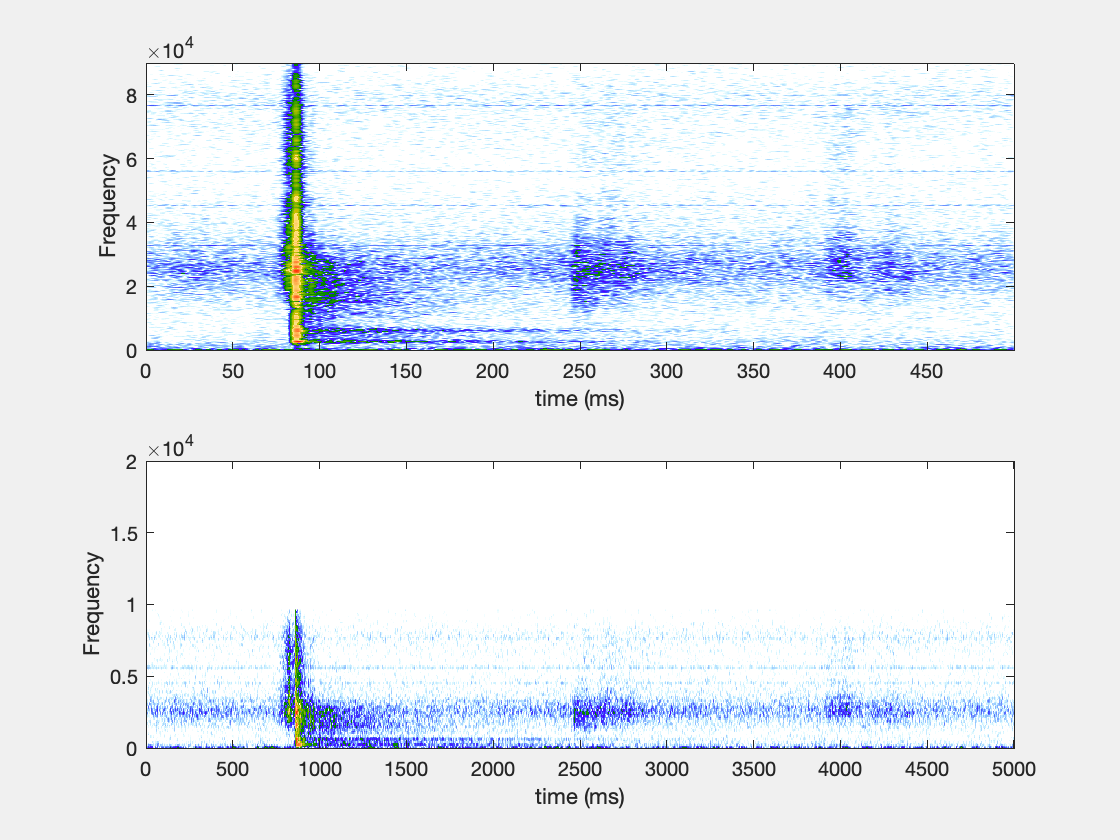


% Noise 
Sound_file = '/Volumes/server_home-1/users/old lab members/Sandra/Lesion/Lesionrecordings/Lesion_Groups/Group4/Group4_20160727/Group4_20160727T195005_C_Group_Variation_0000_0001_0000.mat';
Sound = load(Sound_file);
% calculate spectrogram and plot shifting the SR by 10
figure(3); set(gcf,'Visible','on'); clf;
subplot(2,1,1)
[~] = spec_only_bats(Sound.recsGroup, Sound.fs, DB_noise, 90000);
subplot(2,1,2)
[~] = spec_only_bats(Sound.recsGroup, FS/10, DB_noise, 20000);

%% Internal functions



    function BioSoundObj = runBiosound(Y, FS, F_high)
        % Hard coded parameters for biosound
        % Spectrum parameters
        if nargin<3
            F_high = 50000; % frequency of Low-pass filter Hz
        end
        DBNOISE = 60; % Threshold on amplitude of spectrogram to extract time varying spectral mean and quartiles
        Quartile_values = [0.25, 0.5, 0.75];
        % spectrogram parameters
        Spec_sample_rate = 1000; % sampling rate Hz
        Freq_spacing = 300; % width of the frequency window for the FFT Hz used to be 100
        Min_freq = 300; % high pass filter before FFT Hz
        Max_freq = F_high; % Low pass filter before FFT Hz
        % temporal enveloppe parameters
        Cutoff_freq = 150; % Hz
        Amp_sample_rate = 1000; % Hz
        % Fundamental parameters
        MinSaliency = 0.4; % used to be 0.6
        DebugFigFundest = 0;
        MinFormantFreq = 2000;
        MaxFormantBW = 1000; %500
        WindowFormant = 0.1;
        fprintf(1, 'running Biosound... ')
       
        
        % create the biosound object
        BiosoundObj = py.soundsig.sound.BioSound(py.numpy.array(Y),pyargs('fs',FS));
        % methods(BiosoundFi, '-full') % this command plot all the methods with the available arguments
        
        % Calculate the RMS (lhs std(varargin))
        BioSoundObj.rms = BiosoundObj.sound.std();
        
        % calculate the amplitude enveloppe
        ampenv(BiosoundObj, Cutoff_freq,Amp_sample_rate);
        
        % Calculate the periodicity of the amplitude envelope
        SoundAmp = double(py.array.array('d', py.numpy.nditer(BiosoundObj.amp)));
        [P,F] = pspectrum(SoundAmp,1000);
        [PKS,LOCS]=findpeaks(P);
        AmpPeriodF = F(LOCS(PKS == max(PKS))); % Frequency in hertz of the max peak
        AmpPeriodP = max(PKS)/mean(SoundAmp.^2); % Proportion of power in the max peak of the spectrum
        
        % Store data for the amplitude envelope of the whole sound
        BioSoundObj.amp = SoundAmp;
        BioSoundObj.ampt = double(BiosoundObj.tAmp);
        BioSoundObj.maxAmp = double(BiosoundObj.maxAmp);

        % calculate the spectrum (lhs spectrum(self, f_high, pyargs))
        spectrum(BiosoundObj, F_high)

        % spectral envelope parameters
        BioSoundObj.psd{1} = double(BiosoundObj.psd);
        BioSoundObj.psdf{1} = double(BiosoundObj.fpsd);
        BioSoundObj.meanspect = double(BiosoundObj.meanspect);
        BioSoundObj.stdspect = double(BiosoundObj.stdspect);
        BioSoundObj.kurtosisspect = double(BiosoundObj.kurtosisspect);
        BioSoundObj.skewspect = double(BiosoundObj.skewspect);
        BioSoundObj.entropyspect = double(BiosoundObj.entropyspect);
        BioSoundObj.meantime = double(BiosoundObj.meantime);
        BioSoundObj.stdtime = double(BiosoundObj.stdtime);
        BioSoundObj.kurtosistime = double(BiosoundObj.kurtosistime);
        BioSoundObj.skewtime = double(BiosoundObj.skewtime);
        BioSoundObj.entropytime = double(BiosoundObj.entropytime);
       


        % calculate the spectrogram of the whole sound event(lhs spectroCalc(self, spec_sample_rate,
        % freq_spacing, min_freq, max_freq, pyargs))
        try % For very short sound, the Freq_spacing is too small, doubling if error
            spectroCalc(BiosoundObj, Spec_sample_rate, Freq_spacing, Min_freq,Max_freq)
        catch
            spectroCalc(BiosoundObj, Spec_sample_rate, Freq_spacing.*2, Min_freq,Max_freq)
        end

        % Calculate the mps
        % MPS parameters
        Window = 0.1;% duration of the window in sec when binning the spectrogram
        Norm = 1; % boolean to indicate if you want to normalize or not the MPS (zscore of the spectrogram before 2Dfft
        mpsCalc(BiosoundObj, Window, Norm)
        
        % Calculate time varying spectralmean and spectral quartiles
        Spectro = double(BiosoundObj.spectro);
        maxB = max(max(Spectro));
        minB = maxB-DBNOISE; 
        Spectro(Spectro<minB) =minB;
        Spectro = Spectro-minB;
        Fo = double(BiosoundObj.fo);
        TPoints = size(Spectro,2);
        SpectralMean = nan(1,TPoints);
        Quartile_freq = nan(3,TPoints);
        %         SpectralMax = nan(1,TPoints);
        for tt=1:TPoints
            %             SpectralMax(tt) = Fo(Spectro(:,tt)==max(Spectro(:,tt)));
            PSDSpec = Spectro(:,tt)./(sum(Spectro(:,tt)));
            SpectralMean(tt) = sum(PSDSpec' .* Fo);
            % Find quartile power
            Cum_power = cumsum(Spectro(:,tt));
            Tot_power = sum(Spectro(:,tt));
            Nfreqs = length(Cum_power);
            iq = 1;
            for ifreq=1:Nfreqs
                if (Cum_power(ifreq) > Quartile_values(iq)*Tot_power)
                    Quartile_freq(iq,tt) = Fo(ifreq);
                    iq = iq+1;
                    if (iq > 3)
                        break;
                    end
                end
            end
        end
        
        % calculate the fundamental and related values (lhs fundest(self, maxFund,
        % minFund, lowFc, highFc, minSaliency, debugFig, pyargs)
        % HighFc = 15000Hz by default High frequency cut-off for band-passing the signal prior to auto-correlation in Saliency calculation and fundamental calculation
        Q1mean = mean(Quartile_freq(1,:),2, 'omitnan');
        if Q1mean>18000 % this is a really high pitch vocalization
            HighFc = 94000;
            MaxFund = 23500; %4000
            MinFund = 2*Q1mean/3;
            LowFc = Q1mean/3; %100
            Method = 'Stack';
        else
            HighFc = 18000;
            MaxFund = 4000; %4000
            MinFund = 50;
            LowFc = 50; %100
            Method= 'AC';
        end
        fprintf(1, 'Fundest method = %s  ', Method)
        Timer = tic;
        try
            fundest(BiosoundObj, MaxFund, MinFund,LowFc, HighFc, MinSaliency,DebugFigFundest,MinFormantFreq,MaxFormantBW,WindowFormant,Method)
        catch ME2% increase the Min Fund value such as to look for only high pitch values (smaller time lag/window)
            if contains(ME2.message, 'Lags are too long')
                try
                    fundest(BiosoundObj, MaxFund, MinFund*10,LowFc, HighFc, MinSaliency,DebugFigFundest,MinFormantFreq,MaxFormantBW,WindowFormant,Method)
                catch ME3
                    warning(ME3.identifier,'Error on calculation of fundamental: %s', ME3.message)
                    fundest(BiosoundObj, MaxFund, MinFund*5,LowFc, HighFc, MinSaliency,DebugFigFundest,MinFormantFreq,MaxFormantBW,WindowFormant,Method)
                end
            else
                keyboard
            end
        end
        fprintf(1,'Fund Estimation: %.2f seconds\n', toc(Timer))
        clear Timer
        
        % Only keep values of fundamentals where there is power in the
        % spectrogram
        PowerThresh = 2; %30 used for adult recordings
        Fund = double(BiosoundObj.f0);
        Fund2 = double(BiosoundObj.f0_2);
        MinF0 = floor(min(Fund)/100)*100;
        MaxF0 = ceil(max(Fund)/100)*100;
        if (MaxF0 - MinF0)>8000 % There is definitively a range issue here use the median as a reference
            MF = median(Fund, 'omitnan');
            RangeFund = min(MaxF0-MF,MF-MinF0);
            MaxF0 = MF+RangeFund;
            MinF0 = MF+RangeFund;
        end
        SpectroFo = double(BiosoundObj.fo);
        SpectroRows = logical((SpectroFo>MinF0) .* (SpectroFo<MaxF0));
        PowerSpectroBand = mean(Spectro(SpectroRows,:),1);
        VocOffFund = PowerSpectroBand<PowerThresh;
        Fund(VocOffFund) = nan;
        Fund2(VocOffFund) = nan;
        % when the saliency is very low (<0.4), we do not expect to have high
        % values of fundamental (>1kHz), these are probably wrongly calculated
        Sal = double(BiosoundObj.sal);
        BadSalHighFund = logical((Sal<0.4) .* (Fund>1000)); %Used to be 0.5 for adult recordings
        Fund(BadSalHighFund) = nan;
        Fund2(BadSalHighFund) = nan;


        % Only keep measurements where there is power in amplitude envelope
        VocOff = SoundAmp < (BioSoundObj.maxAmp*0.08);
        BioSoundObj.DurAmpThresh = sum(~VocOff);
        Sal(VocOff) = nan;
        Fund(VocOff) = nan;
        Fund2(VocOff) = nan;
        SpectralMean(VocOff) = nan;
        Quartile_freq(:,VocOff) = nan;
        F1 = double(BiosoundObj.F1);
        F2 = double(BiosoundObj.F2);
        F3 = double(BiosoundObj.F3);
        F1(VocOff) = nan;
        F2(VocOff) = nan;
        F3(VocOff) = nan;
        
        
        MeanFund = mean(Fund, 'omitnan');
        MeanSpectralMean = mean(SpectralMean, 'omitnan');
        MeanSal = mean(Sal, 'omitnan');
        MeanF1 = mean(F1, 'omitnan');
        MeanF2 = mean(F2, 'omitnan');
        MeanF3 = mean(F3, 'omitnan');
        MeanQuartile_Freq = mean(Quartile_freq,2, 'omitnan')';

        
        
        
        % Add some fields to our output
        BioSoundObj.samprate = double(BiosoundObj.samprate);
        BioSoundObj.AmpPeriodF = AmpPeriodF;
        BioSoundObj.AmpPeriodP = AmpPeriodP;
        BioSoundObj.SpectralMean = SpectralMean;
        BioSoundObj.MeanSpectralMean = MeanSpectralMean;
        BioSoundObj.Q1t = Quartile_freq(1,:);
        BioSoundObj.Q2t = Quartile_freq(2,:);
        BioSoundObj.Q3t = Quartile_freq(3,:);
        BioSoundObj.MeanQ1t = MeanQuartile_Freq(:,1);
        BioSoundObj.MeanQ2t = MeanQuartile_Freq(:,2);
        BioSoundObj.MeanQ3t = MeanQuartile_Freq(:,3);
        BioSoundObj.spectro = double(BiosoundObj.spectro);
        BioSoundObj.to = double(BiosoundObj.to);
        BioSoundObj.fo = double(BiosoundObj.fo);
        BioSoundObj.F1 = F1;
        BioSoundObj.MeanF1 = MeanF1;
        BioSoundObj.F2 = F2;
        BioSoundObj.MeanF2 = MeanF2;
        BioSoundObj.F3 = F3;
        BioSoundObj.MeanF3 = MeanF3;
        BioSoundObj.sal = Sal;
        BioSoundObj.MeanSal = MeanSal;
        BioSoundObj.f0 = Fund;
        BioSoundObj.MeanF0 = MeanFund;
        BioSoundObj.f0_2 = Fund2;
        BioSoundObj.minf0 = double(BiosoundObj.minfund);
        BioSoundObj.maxf0 = double(BiosoundObj.maxfund);
        BioSoundObj.cvfund = double(BiosoundObj.cvfund);
        BioSoundObj.voice2percent = double(BiosoundObj.voice2percent);
        BioSoundObj.sound = double(BiosoundObj.sound);
        BioSoundObj.mps = double(BiosoundObj.mps);
        BioSoundObj.wf = double(BiosoundObj.wf);
        BioSoundObj.wt = double(BiosoundObj.wt);

        BioSoundObj.hashid = double(BiosoundObj.hashid);
    end

    function plotBiosound(BiosoundObj, F_high, Sound2,FormantPlot)
        if nargin<3
            Sound2 = []; % when the time window for analysis is enlarged to calculate the MPS
        end
        if nargin<4
            FormantPlot=1;
        end
        % Plot the results of biosound calculations
        ss1 = subplot(3,1,1);
        ColorCode = get(groot,'DefaultAxesColorOrder');
        DBNOISE =60;
        f_low = 0;
        logB = BiosoundObj.spectro;
        maxB = max(max(logB));
        minB = maxB-DBNOISE;
        
        imagesc(double(BiosoundObj.to)*1000,double(BiosoundObj.fo),logB);          % to is in seconds
        axis xy;
        caxis('manual');
        caxis([minB maxB]);
        cmap = spec_cmap();
        colormap(cmap);
        %         colorbar()
        
        v_axis = axis;
        v_axis(3)=f_low;
        v_axis(4)=F_high;
        axis(v_axis);
        xlabel('time (ms)'), ylabel('Frequency');
        
        hold on
        plot(double(BiosoundObj.to)*1000,double(BiosoundObj.SpectralMean),'k-','LineWidth',2)
        hold on
        plot(double(BiosoundObj.to)*1000,double(BiosoundObj.Q2t),'Color',ColorCode(6,:),'LineWidth',2)
        
        % Plot the fundamental and formants if they were calculated
        %     if double(BiosoundFi.sal)>MinSaliency
        Legend = {sprintf('SpecMean %.1fHz', mean(double(BiosoundObj.SpectralMean), 'omitnan')) sprintf('SpecMed %.1fHz',mean(double(BiosoundObj.Q2t), 'omitnan'))  sprintf('F0 %.1fHz', mean(double(BiosoundObj.f0),'omitnan')) 'Formant1' 'Formant2' 'Formant3'};
        IndLegend = [1 2];
        if ~isempty(double(BiosoundObj.f0))
            hold on
            plot(double(BiosoundObj.to)*1000,double(BiosoundObj.f0),'r-','LineWidth',2)
            IndLegend = [IndLegend 3];
        end
        if FormantPlot
            hold on
            plot(double(BiosoundObj.to)*1000,double(BiosoundObj.F1),'Color',ColorCode(4,:),'LineWidth',2)
            hold on
            plot(double(BiosoundObj.to)*1000,double(BiosoundObj.F2),'Color',ColorCode(2,:),'LineWidth',2)
            hold on
            if any(~isnan(double(BiosoundObj.F3)))
                plot(double(BiosoundObj.to)*1000,double(BiosoundObj.F3),'Color',ColorCode(7,:),'LineWidth',2)
                IndLegend = [IndLegend 4:6];
            else
                IndLegend = [IndLegend 4:5];
            end
        end
        
        yyaxis right
        hold on
        plot(double(BiosoundObj.to)*1000,double(BiosoundObj.sal),'m-','LineWidth',2)
        legend([Legend(IndLegend) sprintf('Pitch Sal %.2f', mean(double(BiosoundObj.sal), 'omitnan'))], 'Location','southoutside','NumColumns',length(IndLegend)+1)
%         hold on
%         plot(double(BiosoundObj.to)*1000,double(BiosoundObj.sal2),'m--','LineWidth',2)
        ylabel('Pitch Saliency')
        ylim([0 1])
        ss1.YColor = 'm';
        hold off
        
        ss2=subplot(3,1,2);
        yyaxis left
%         if ~isempty(Sound2)
%             Sound = Sound2;
%         else
            Sound = double(BiosoundObj.sound);
%         end
        plot((1:length(Sound))/BiosoundObj.samprate*1000,Sound, 'k-','LineWidth',2)
        hold on
        YLIM = get(gca,'YLim');
        YLIM = max(abs(YLIM)).*[-1 1];
        set(gca, 'YLim', YLIM)
        SoundAmp = double(py.array.array('d', py.numpy.nditer(BiosoundObj.amp)));
        ss2.YColor = 'k';
         % Plot the onsets and offsets of each sound element according to
        % Piezo manual curation
        if isfield(BiosoundObj, 'OnOffSets_elmts')
            for Ne = 1:size(BiosoundObj.OnOffSets_elmts,1)
                ColorInd = rem(Ne,size(ColorCode,1));
                if ColorInd==0
                    ColorInd = size(ColorCode,1);
                end
                MaxX = min(length(Sound),BiosoundObj.OnOffSets_elmts(Ne,2));
                plot((BiosoundObj.OnOffSets_elmts(Ne,1):MaxX)/BiosoundObj.samprate*1000,Sound(BiosoundObj.OnOffSets_elmts(Ne,1):MaxX),'LineStyle','-','LineWidth',2,'Color',ColorCode(ColorInd,:), 'DisplayName',sprintf('Elmt %d',Ne))
            end
            legend('AutoUpdate', 'Off')
        end
        
        yyaxis right
        plot(double(BiosoundObj.ampt)*1000,double(SoundAmp), 'r-', 'LineWidth',2)
        YLIM = get(gca,'YLim');
        YLIM = max(abs(YLIM)).*[-1 1];
        set(gca, 'YLim', YLIM)
        set(gca, 'XLim', v_axis(1:2))
        xlabel('Time (ms)')
        ylabel('sound amplitude')
        if ~isempty(Sound2)
            title(sprintf('AmpPeriodicity = %.3f AmpPF = %.1f Hz  Note: Sound enlarged for MPS calculations',BiosoundObj.AmpPeriodP, BiosoundObj.AmpPeriodF))
        else
            title(sprintf('AmpPeriodicity = %.3f AmpPF = %.1f Hz',BiosoundObj.AmpPeriodP, BiosoundObj.AmpPeriodF))
        end
        ss2.YColor = 'r';
        hold off

        subplot(3,1,3);
        DBNOISE=60;
        YLim = [0 max(BiosoundObj.wf*10^3)];
%         XLim = [min(BiosoundObj.wt) max(BiosoundObj.wt)];
        XLim = [-300 300];
        Wf_i = logical((BiosoundObj.wf*10^3>=YLim(1)).* (BiosoundObj.wf*10^3<=YLim(2)));
        Wt_i = logical((BiosoundObj.wt>=XLim(1)).* (BiosoundObj.wt<=XLim(2)));
        BiosoundObj.mps = BiosoundObj.mps(Wf_i, Wt_i);
        Wf_local = BiosoundObj.wf(Wf_i);
        Wt_local = BiosoundObj.wt(Wt_i);
        MPS4plot = 10*log10(BiosoundObj.mps);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
        Im = imagesc(MPS4plot);
        axis xy
        colormap(Im.Parent,'jet');
        colorbar()
        xlabel('Temporal Frequency (Hz)')
        ylabel('Spectral Frequency (Cycles/kHz)')
        % get nice X and y tick labels
        MaxWf = max(floor(Wf_local*10^3));
        YTickLabel=0:MaxWf;
        YTick = nan(length(YTickLabel),1);
        for yy=1:length(YTick)
            YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
        end
        set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
        MaxWt = max(floor(Wt_local*10^-2))*10^2;
        XTickLabel = -MaxWt:100:MaxWt;
        XTick = nan(length(XTickLabel),1);
        for xx=1:length(XTick)
            [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
        end
        set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    end